load ryan3_data.mat
%load ryan3_model_FirstCC_RUL.mat

generate_model = true
% generate_model = false
if generate_model == false
    load ryan3_model_FirstCC_RUL.mat
end

# 필요한 데이타 로딩

%% https://kr.mathworks.com/help/matlab/ref/load.html

load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_IcFirst_RUL','y_trainValid_IcFirst_RUL')
%load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_IcFirst_RUL','y_trainValid_IcFirst_RUL')



# 선형회귀 - 모델 생성


%% https://kr.mathworks.com/help/matlab/ref/load.html
% load('ryan3_data.mat','x_trainValid_IcFirstFull_RUL','x_trainValid_IcFirst_RUL','y_trainValid_IcFirst_RUL')

if generate_model
mdlFull = fitlm(x_trainValid_IcFirstFull_RUL,y_trainValid_IcFirst_RUL)

mdlFull = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20 + x21 + x22 + x23 + x24 + x25 + x26 + x27 + x28 + x29 + x30 + x31 + x32 + x33 + x34 + x35 + x36 + x37 + x38 + x39 + x40 + x41 + x42 + x43 + x44 + x45 + x46 + x47 + x48 + x49 + x50 + x51 + x52 + x53 + x54 + x55 + x56 + x57 + x58 + x59 + x60 + x61 + x62 + x63 + x64 + x65 + x66 + x67 + x68 + x69 + x70 + x71 + x72 + x73 + x74 + x75 + x76 + x77 + x78 + x79 + x80 + x81 + x82 + x83 + x84 + x85 + x86 + x87 + x88 + x89 + x90 + x91 + x92 + x93 + x94 + x95 + x96 + x97 + x98 + x99 + x100

Estimated Coefficients:
                   Estimate      SE         tStat        pValue  
                   ________    _______    __________    _________

    (Intercept)      14.101     14.126       0.99822

mdl = fitlm(x_trainValid_IcFirst_RUL,y_trainValid_IcFirst_RUL)

mdl = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4 + x5 + x6 + x7 + x8 + x9 + x10 + x11 + x12 + x13 + x14 + x15 + x16 + x17 + x18 + x19 + x20

Estimated Coefficients:
                   Estimate      SE        tStat        pValue  
                   ________    _______    ________    __________

    (Intercept)      0.4149     0.5099     0.81369       0.41807
    x1             -0.21489    0.33095     -0.6493       0.51787
    x2              0.17704    0.39234     0.45124       0.65295
    x3             -0.50363    0.46835     -1.0753       0.28524
    x4              0.02596    0.52221    0.049712       0.96047
    x5              0.16015    0.76551      0.2092       0.83478
    x6             -0.36978    0.66408    -0.55


ryan3_model_gen_FirstCC_RUL_desc = "ryan3_model_FirstCC_RUL"

ryan3_model_gen_FirstCC_RUL_desc = "ryan3_model_FirstCC_RUL"

save('ryan3_model_FirstCC_RUL.mat','ryan3_model_gen_FirstCC_RUL_desc' )
save('ryan3_model_FirstCC_RUL.mat','mdlFull' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','mdl' ,'-append')

end

# 선형회귀 - 예측 - 100 

#### 전류 패턴에 따른 라이프 사이클 예측 ..

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.


coeffFull = mdlFull.Coefficients.Estimate

coeffFull = 	1.0e+03 *

    0.0141
         0
    0.0004
    0.0008
   -0.0038
    0.0019
   -0.0003
   -0.0740
    0.0752
   -0.1929


x_trainValid_IcFirstFull_RUL(1,:)

ans =          0    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.2498    0.7494    0.7494    0.7495    0.7495    0.7494    0.7494    0.7494    0.7494    0.7495    0.7493    0.7494    0.7493    0.7494    0.7453    0.7493    0.7495    0.7492    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7494    0.7495    0.7495    0.7494    0.7496    0.7495    0.7495    0.7494    0.7495    0.7494    0.7494    0.7494    0.7495    0.7495    0.7451    0.7351


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhatFull_trainValid = x_trainValid_IcFirstFull_RUL*coeffFull(2:101)+coeffFull(1)

yhatFull_trainValid =     0.0002
    0.0057
    0.0079
    0.0192
    0.0467
    0.0093
    0.0403
    0.0923
    0.0426
    0.0125


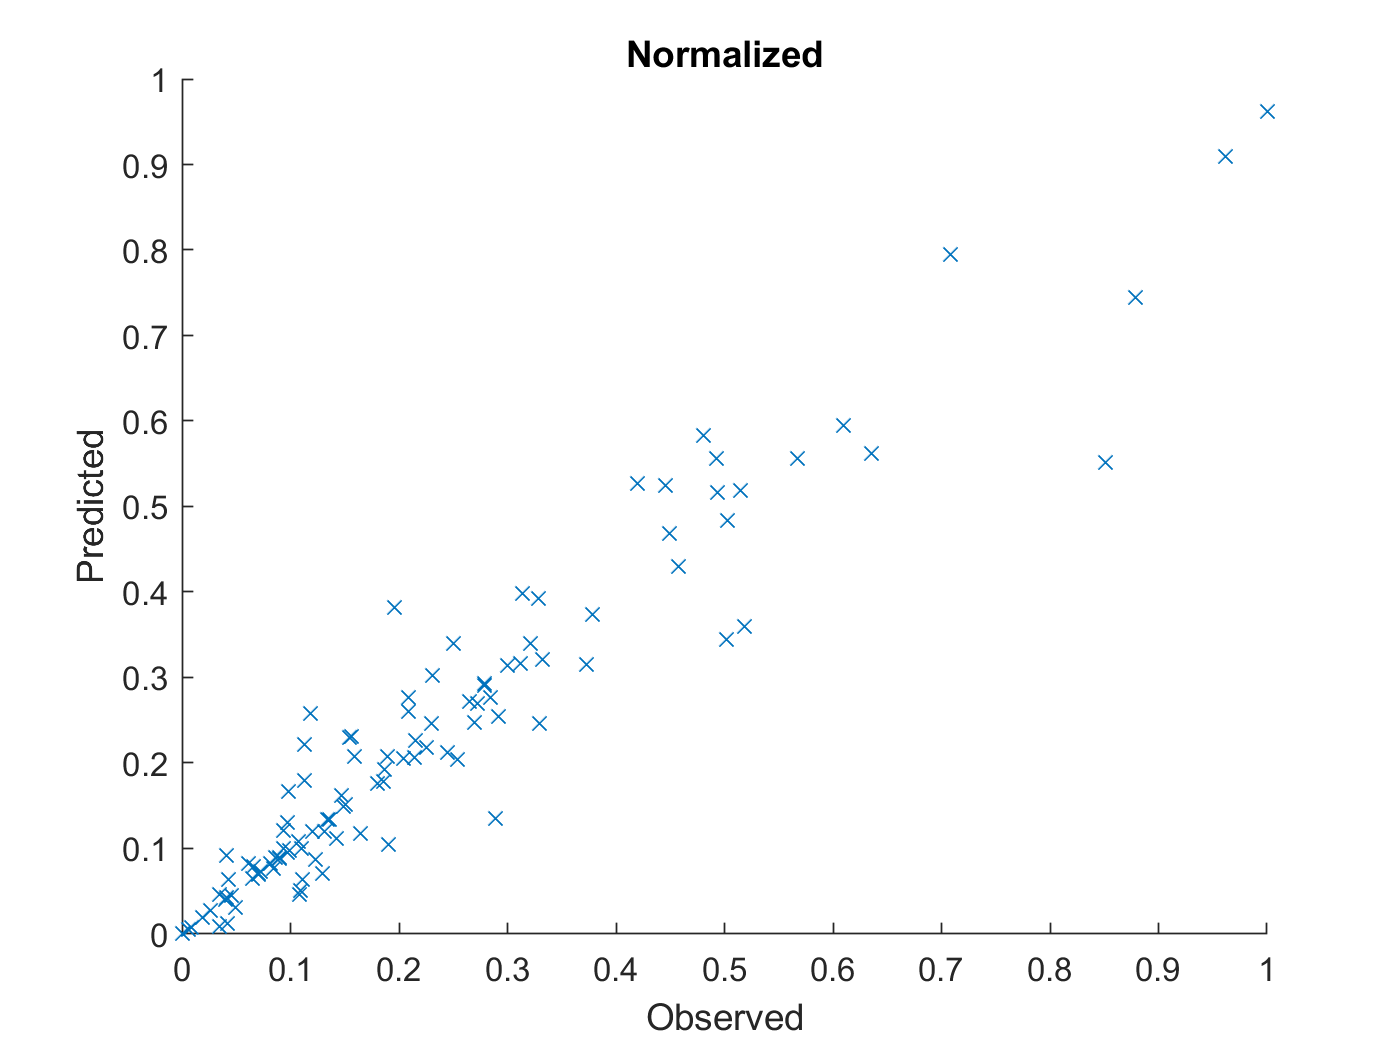

figure
hold on
plot(y_trainValid_IcFirst_RUL,yhatFull_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

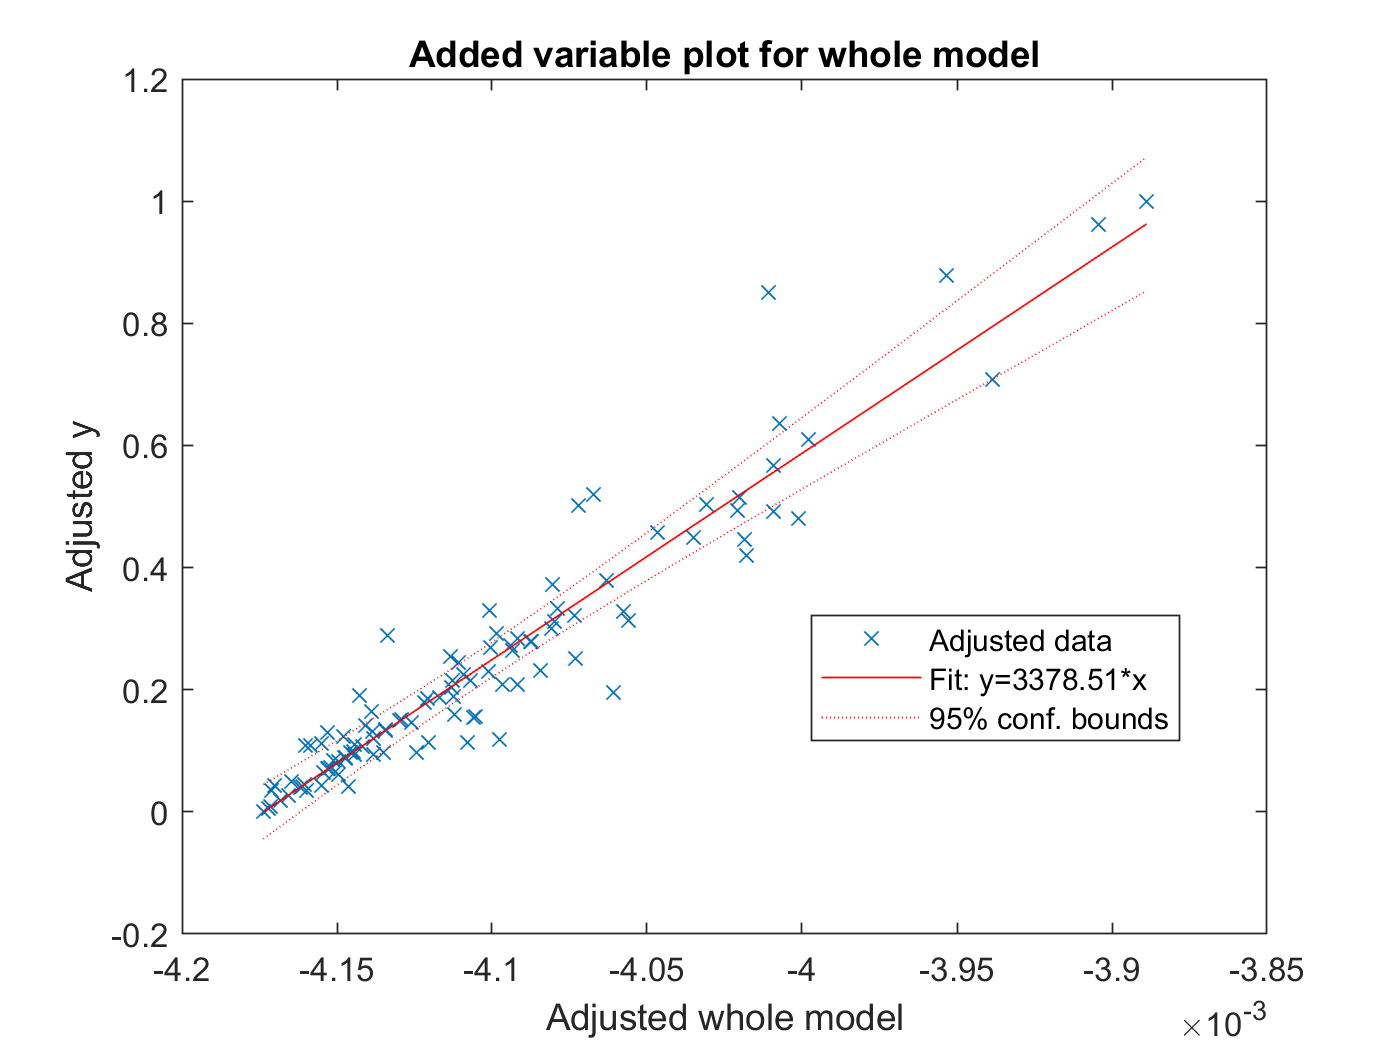


%capHat = Ic(1)

plot(mdlFull)

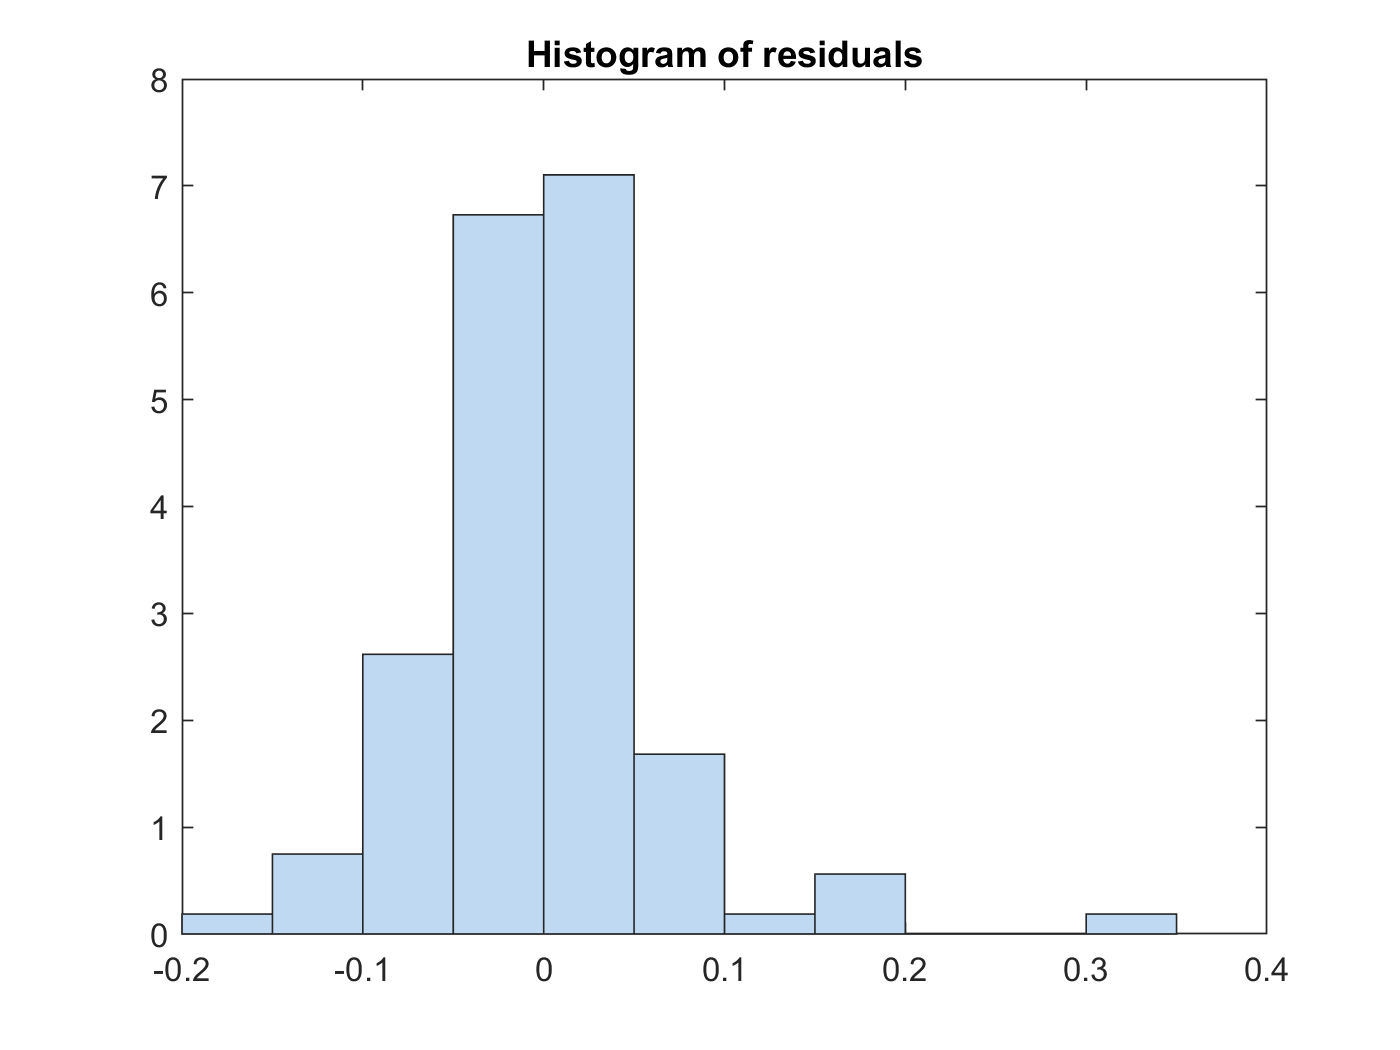

plotResiduals(mdlFull)



% yfit_trainValid = predict(mdlFull,Ic)
yfitFull_trainValid = predict(mdlFull,x_trainValid_IcFirstFull_RUL)

yfitFull_trainValid =     0.0002
    0.0057
    0.0079
    0.0192
    0.0467
    0.0093
    0.0403
    0.0923
    0.0426
    0.0125


yfitFull_test = predict(mdlFull,x_test_IcFirstFull_RUL)

yfitFull_test =    -0.1880
    0.4526
  -24.5142
    0.0844
    0.2026
    2.7145
    0.2550
    0.3868
    0.0240
    0.4998




yFull_trainValid= y_trainValid_IcFirst_RUL

yFull_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test_IcFirst_RUL

y_test_IcFirst_RUL =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719


# denormalize


yfitFull_trainValid = yfitFull_trainValid * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
yFull_trainValid = yFull_trainValid * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
yfitFull_test = yfitFull_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
%Y_test_IcFirst_RUL = y_test_IcFirst_RUL * yrate_IcFirst_RUL + ymin_IcFirst_RUL;


yFull_trainValid_diff = horzcat(yFull_trainValid,(yFull_trainValid-yfitFull_trainValid))

yFull_trainValid_diff = 	1.0e+03 *

    0.1090   -0.0002
    0.1150   -0.0001
    0.1180    0.0006
    0.1290   -0.0004
    0.1460   -0.0126
    0.1460    0.0271
    0.1520    0.0002
    0.1530   -0.0541
    0.1530   -0.0013
    0.1540    0.0318


yFull_trainValid_diff_percentage = abs(yFull_trainValid-yfitFull_trainValid)./yFull_trainValid.*100

yFull_trainValid_diff_percentage =     0.1695
    0.0876
    0.4894
    0.3336
    8.6585
   18.5436
    0.1268
   35.3289
    0.8382
   20.6218


yFull_trainValid_diff_percentage_avg = sum(yFull_trainValid_diff_percentage)/length(yFull_trainValid_diff_percentage)

yFull_trainValid_diff_percentage_avg = 11.0131




MAE = mean(abs(yfitFull_trainValid-yFull_trainValid))

MAE = 39.9619

adjMAE = MAE/range(yFull_trainValid)

adjMAE = 0.0376

range(yFull_trainValid) % yFull_trainValid = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(yFull_trainValid - yhatFull_trainValid)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1150
    0.1180
    0.1290
    0.1460
    0.1460
    0.1520
    0.1529
    0.1530
    0.1540


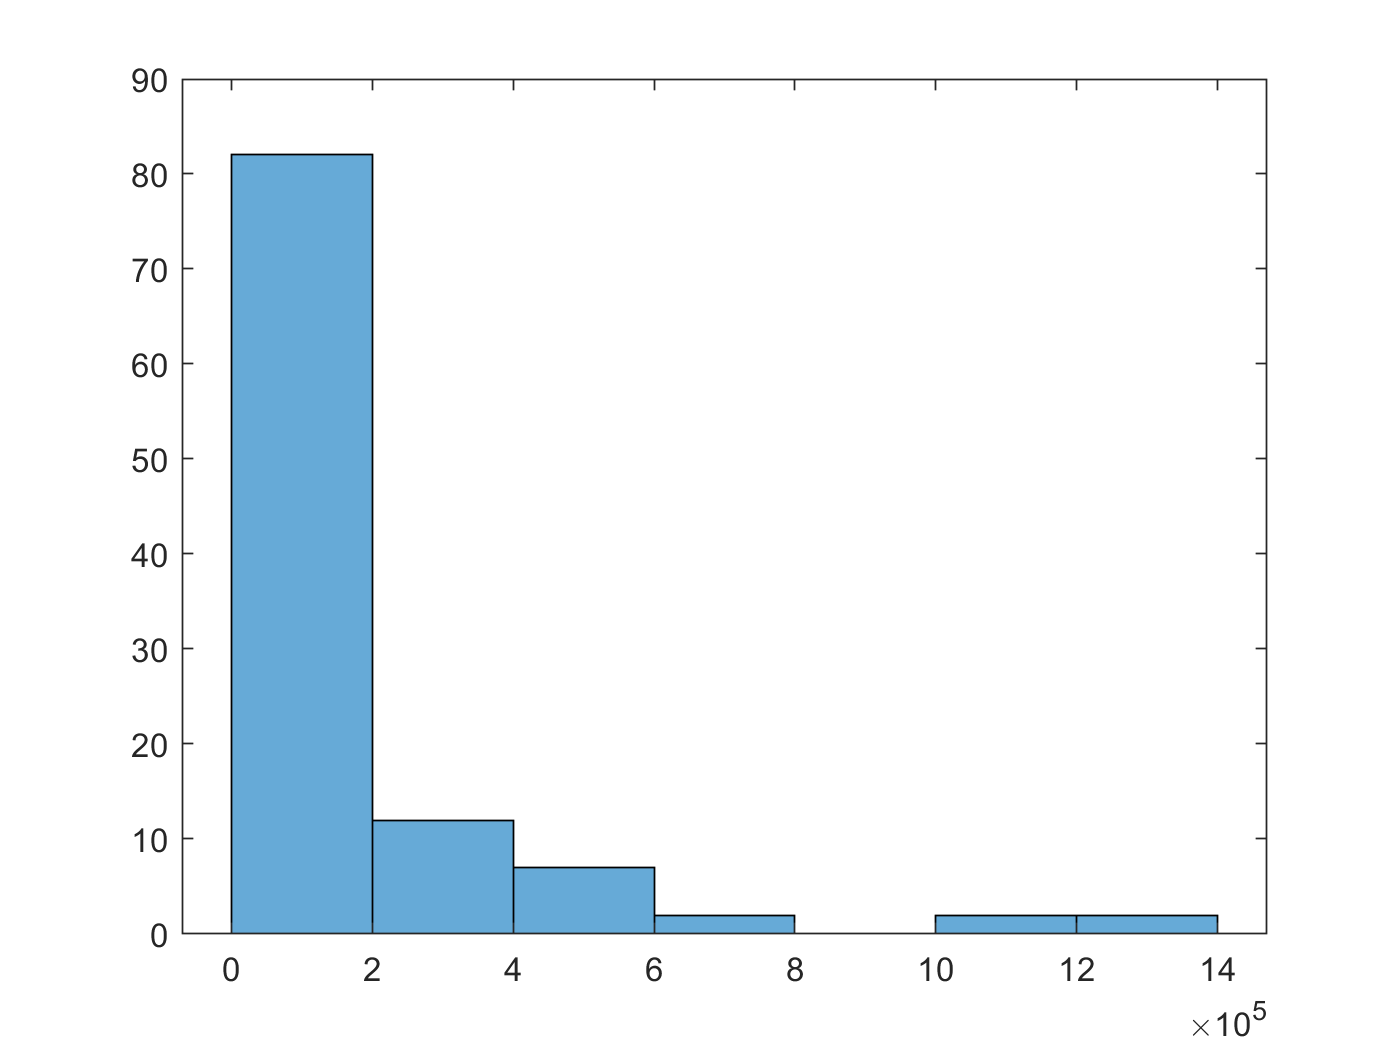

(yFull_trainValid - yhatFull_trainValid).^2;   % Squared Error
histogram((yFull_trainValid - yhatFull_trainValid).^2)

mean((yFull_trainValid - yhatFull_trainValid).^2);   % Mean Squared Error
RMSE = sqrt(mean((yFull_trainValid - yhatFull_trainValid).^2))  % Root Mean Squared Error

RMSE = 420.2406

(Y_test_IcFirst_RUL - yfitFull_test) 

ans = 	1.0e+04 *

    0.0231
   -0.0422
    2.6128
    0.0023
   -0.0085
   -0.2722
   -0.0064
   -0.0165
    0.0279
   -0.0136


RMSE_test = sqrt(mean((Y_test_IcFirst_RUL - yfitFull_test).^2))

RMSE_test = 7.5860e+03


Y_test_IcFirst_RUL - yfitFull_test

ans = 	1.0e+04 *

    0.0231
   -0.0422
    2.6128
    0.0023
   -0.0085
   -0.2722
   -0.0064
   -0.0165
    0.0279
   -0.0136


yFull_test_diff = horzcat(Y_test_IcFirst_RUL,(Y_test_IcFirst_RUL-yfitFull_test))

yFull_test_diff = 	1.0e+04 *

    0.0140    0.0231
    0.0168   -0.0422
    0.0203    2.6128
    0.0222    0.0023
    0.0239   -0.0085
    0.0270   -0.2722
    0.0316   -0.0064
    0.0355   -0.0165
    0.0414    0.0279
    0.0504   -0.0136


yFull_test_diff_percentage = abs(Y_test_IcFirst_RUL-yfitFull_test)./Y_test_IcFirst_RUL.*100

yFull_test_diff_percentage = 	1.0e+04 *

    0.0165
    0.0251
    1.2871
    0.0011
    0.0036
    0.1008
    0.0020
    0.0046
    0.0068
    0.0027


yFull_test_diff_percentage_avg = sum(yFull_test_diff_percentage)/length(yFull_test_diff_percentage)

yFull_test_diff_percentage_avg = 1.2135e+03

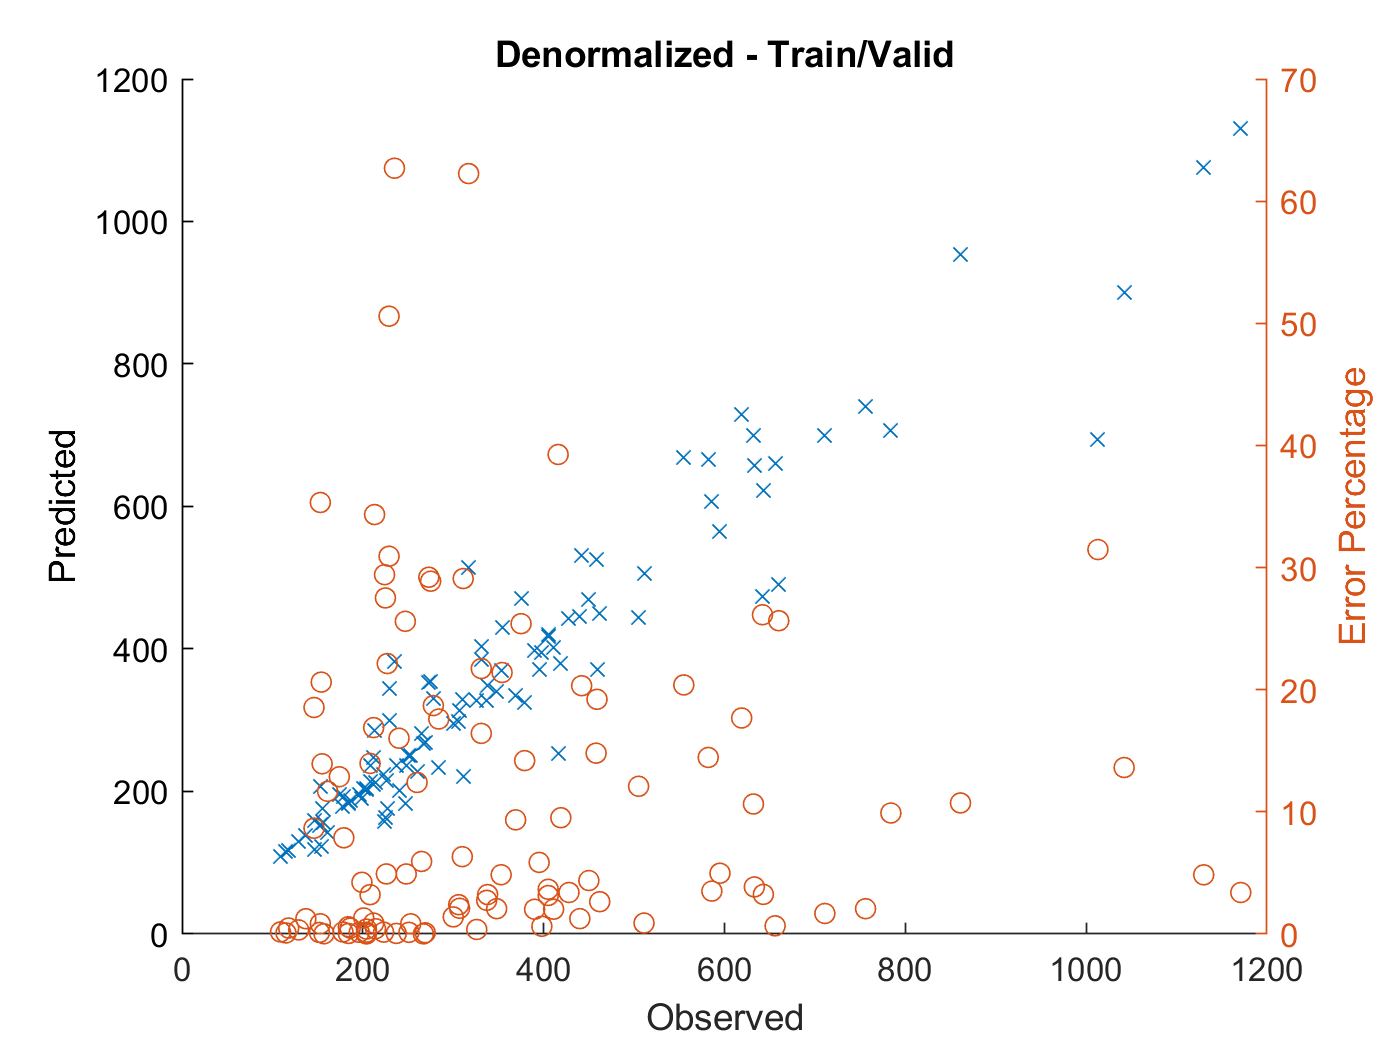


figure
hold on
plot(yFull_trainValid,yfitFull_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")


yyaxis right
ylabel('Error Percentage')
plot(yFull_trainValid,yFull_trainValid_diff_percentage,'o');

hold off
title 'Denormalized - Train/Valid'

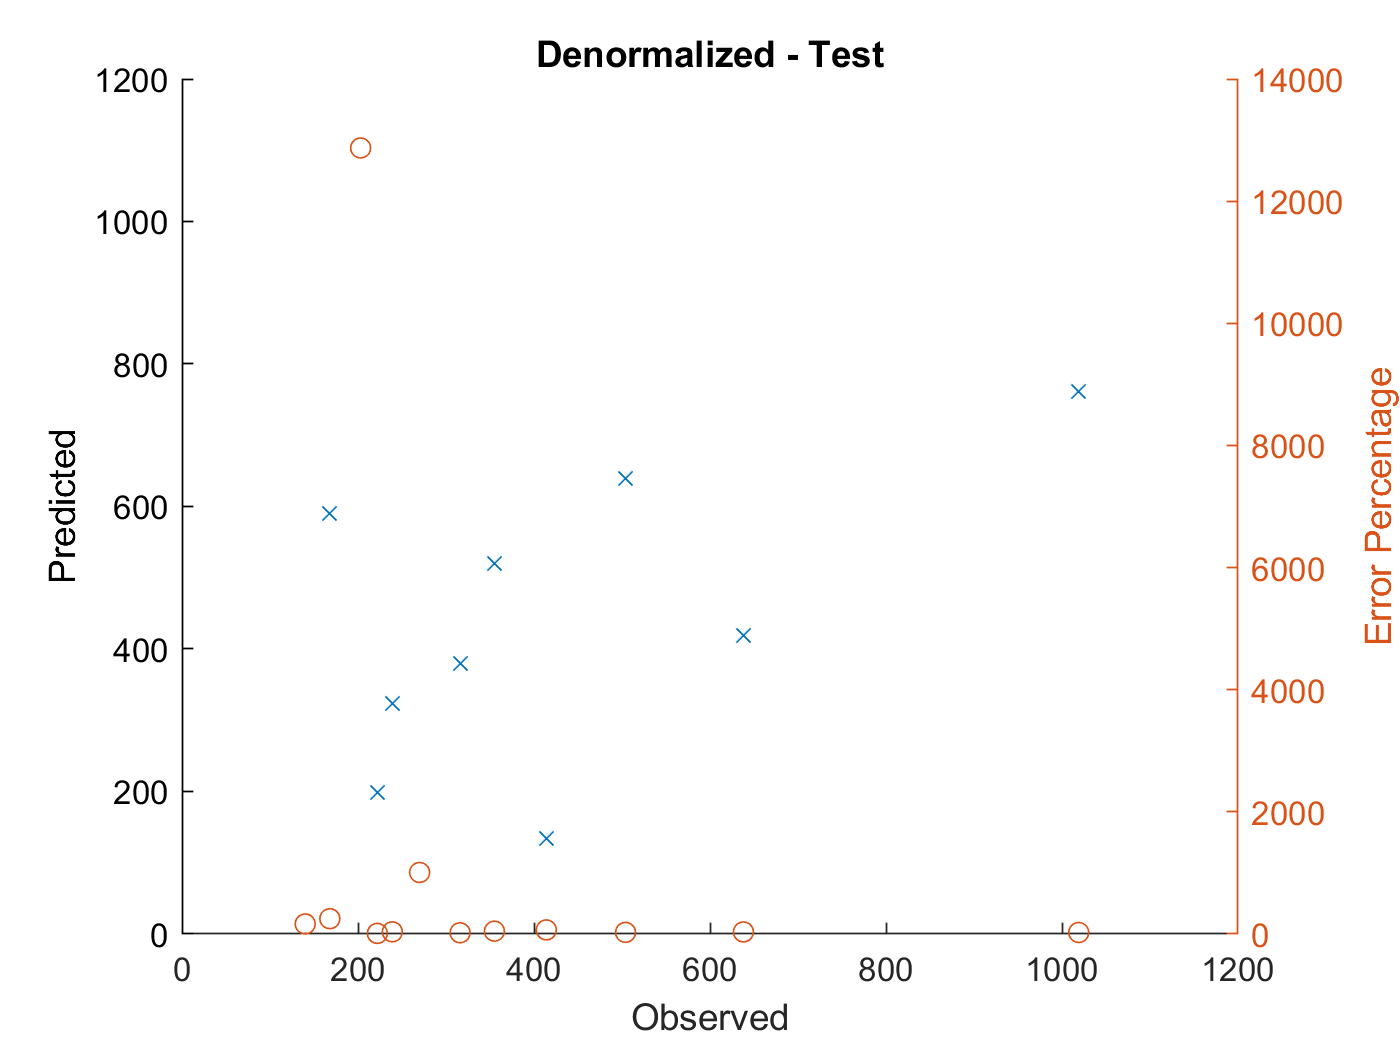


figure
hold on
plot(Y_test_IcFirst_RUL,yfitFull_test,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_IcFirst_RUL,yFull_test_diff_percentage,'o');

hold off
title 'Denormalized - Test'


% 테스트 셋에서는 예측이 전혀 안된다.



# 선형회귀 - 예측 - 20

#### 전류 패턴에 따른 라이프 사이클 예측 - 100개가 아니 20개로 

#### 선형회귀 - 정규화 필요 없지만 정규화해도 된다. 다른 머신러닝 방법을 위해 정규화 된것을 사용하자.

coeff = mdl.Coefficients.Estimate

coeff =     0.4149
   -0.2149
    0.1770
   -0.5036
    0.0260
    0.1601
   -0.3698
   -0.1214
    0.4558
   -0.2644


x_trainValid_IcFirst_RUL(1,:)

ans =     0.1998    0.2498    0.7494    0.7494    0.7485    0.7494    0.7494    0.7495    0.7494    0.7457    0.7156    0.6890    0.6641    0.6316    0.4004    0.1249    0.1050    0.0082         0         0


training set 에서는 정말 잘 동작함.

RMSE 가 정말 작다.

yhat_trainValid = x_trainValid_IcFirst_RUL*coeff(2:21)+coeff(1)

yhat_trainValid =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


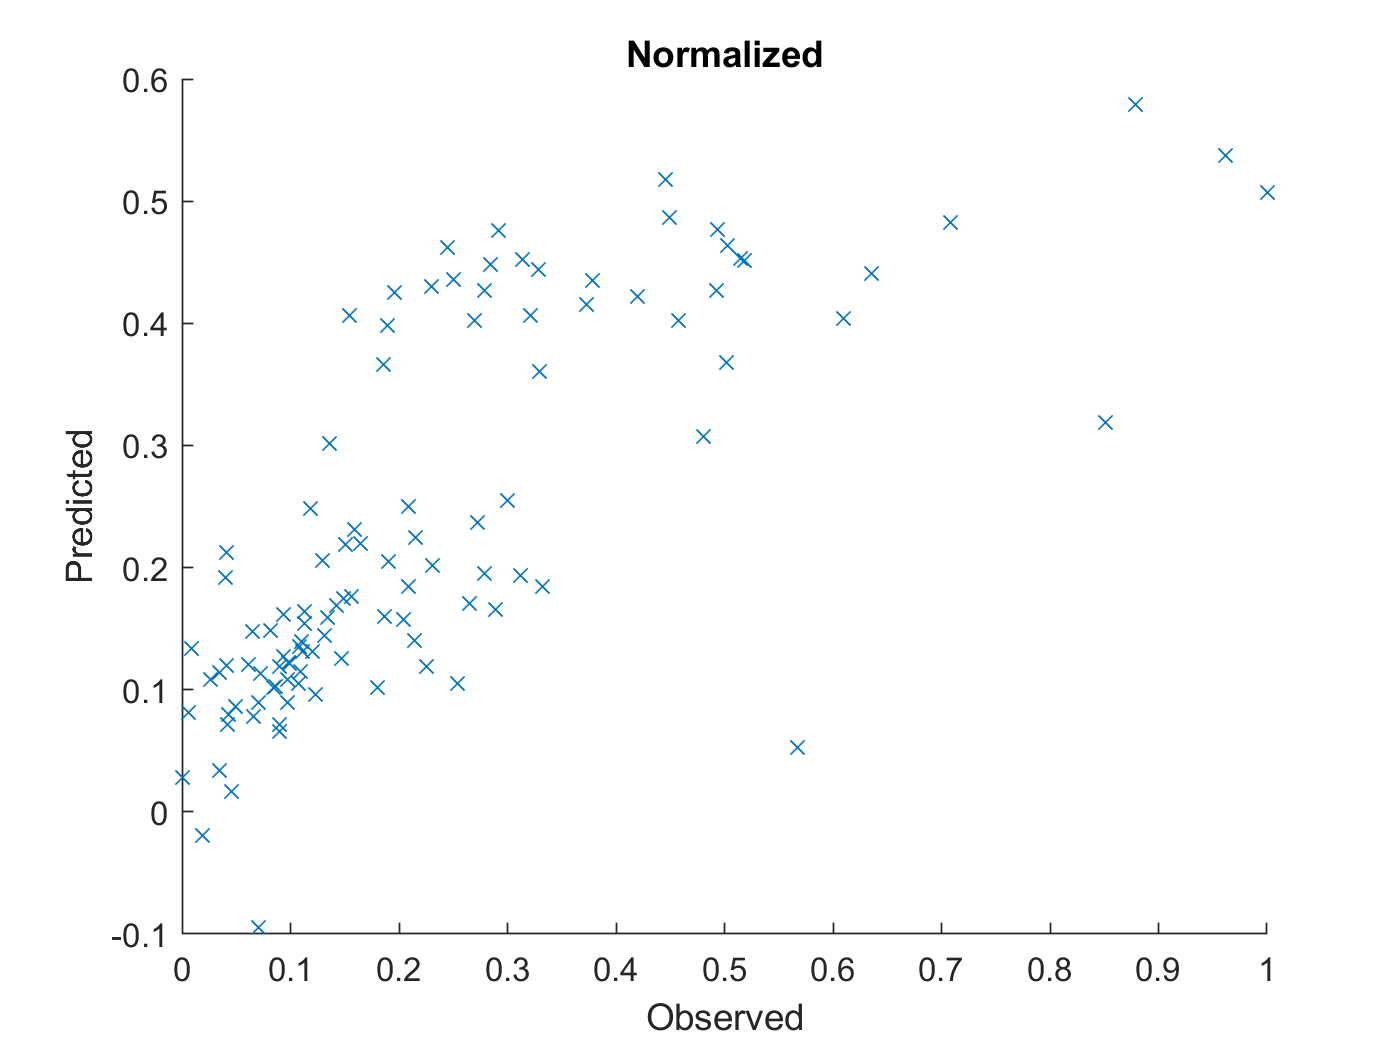


figure
hold on
plot(y_trainValid_IcFirst_RUL,yhat_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")
hold off
title 'Normalized'

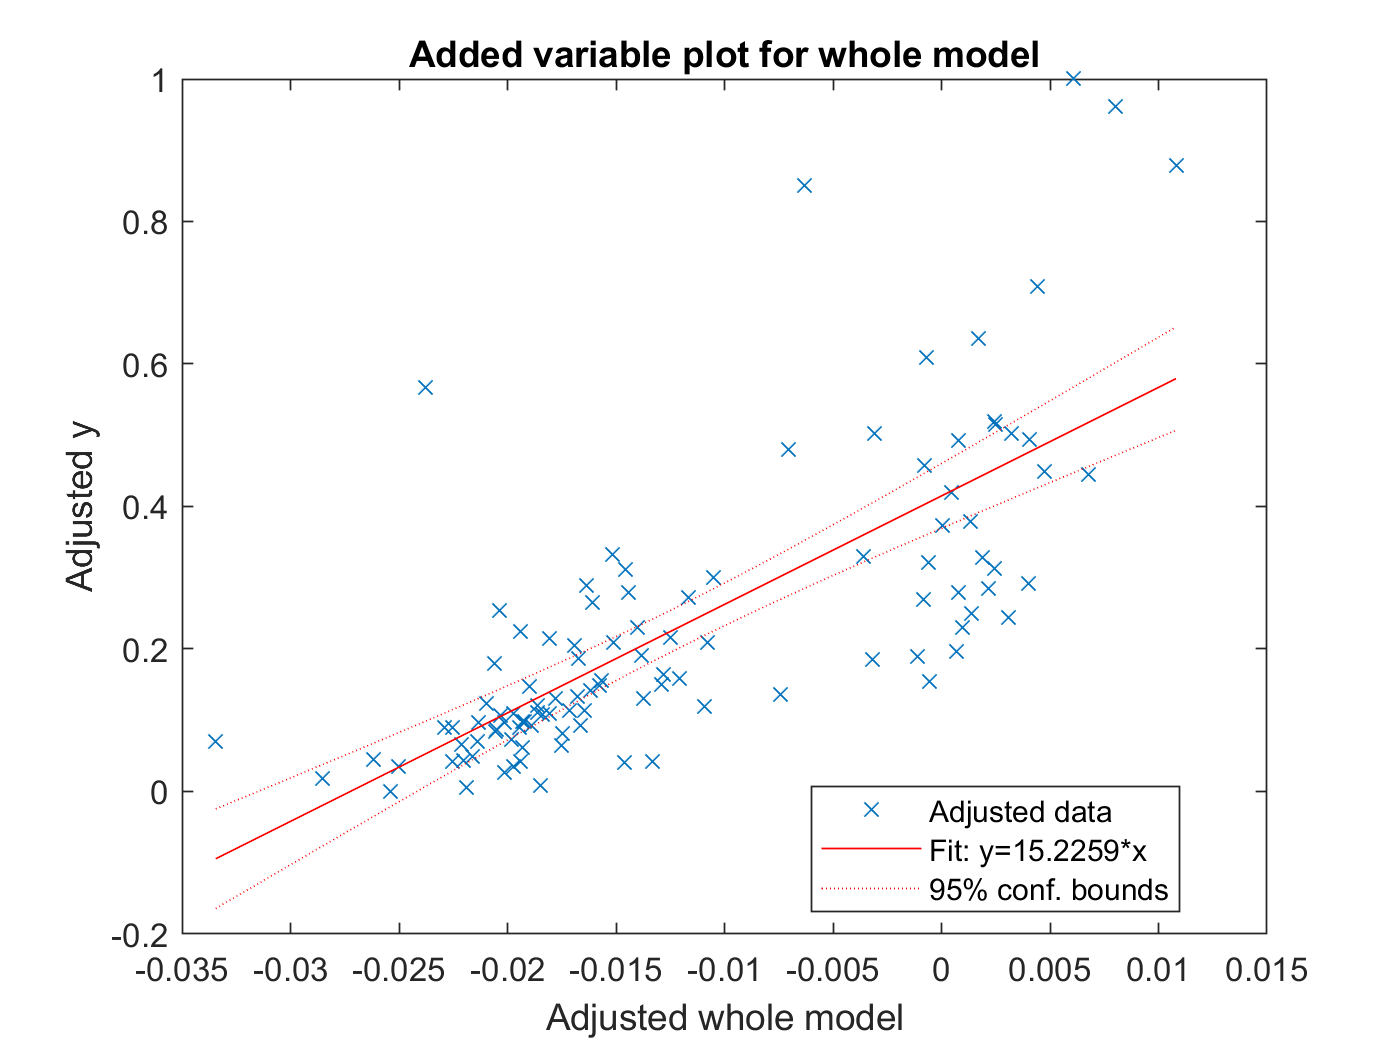


%capHat = Ic(1)

plot(mdl)

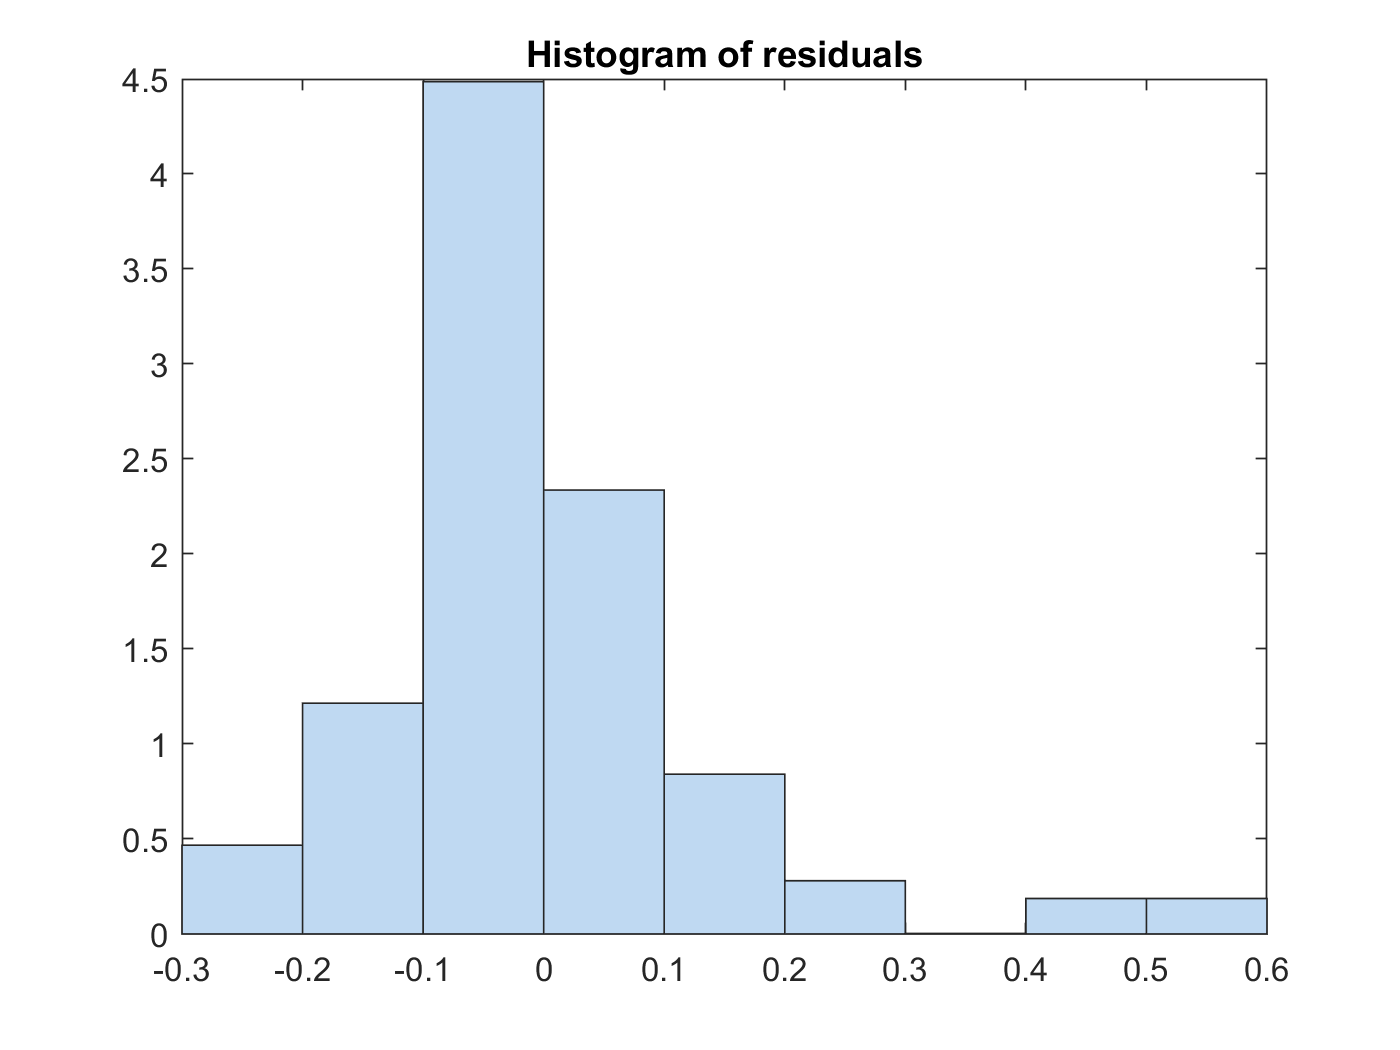

plotResiduals(mdl)

# 선형회귀 - 예측 - 20

% yfit_trainValid = predict(mdl,Ic)
yfit_trainValid = predict(mdl,x_trainValid_IcFirst_RUL)

yfit_trainValid =     0.0282
    0.0816
    0.1337
   -0.0197
    0.1144
    0.0339
    0.1922
    0.2123
    0.1194
    0.0717


yfit_test = predict(mdl,x_test_IcFirst_RUL)

yfit_test =     0.0222
    0.1122
    0.1233
    0.0877
    0.1083
    0.1750
    0.1750
    0.4429
    0.3961
    0.5218




y_trainValid= y_trainValid_IcFirst_RUL

y_trainValid =          0
    0.0056
    0.0085
    0.0188
    0.0348
    0.0348
    0.0405
    0.0414
    0.0414
    0.0424


y_test_IcFirst_RUL

y_test_IcFirst_RUL =     0.0292
    0.0556
    0.0885
    0.1064
    0.1224
    0.1516
    0.1949
    0.2316
    0.2872
    0.3719


# denormaize


yfit_trainValid = yfit_trainValid * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
y_trainValid = y_trainValid * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
yfit_test = yfit_test * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
%Y_test_IcFirst_RUL = y_test_IcFirst_RUL * yrate_IcFirst_RUL + ymin_IcFirst_RUL;



MAE = mean(abs(yfit_trainValid-y_trainValid))

MAE = 99.5134

adjMAE = MAE/range(y_trainValid)

adjMAE = 0.0937

range(y_trainValid) % y_trainValid = range(X)는 X에 포함된 표본 데이터의 최댓값과 최솟값 간의 차이를 반환합니다.

ans = 1062


(y_trainValid - yhat_trainValid)    % Errors

ans = 	1.0e+03 *

    0.1090
    0.1149
    0.1179
    0.1290
    0.1459
    0.1460
    0.1518
    0.1528
    0.1529
    0.1539


(y_trainValid - yhat_trainValid).^2;   % Squared Error
histogram((y_trainValid - yhat_trainValid).^2)

mean((y_trainValid - yhat_trainValid).^2);   % Mean Squared Error
RMSE = sqrt(mean((y_trainValid - yhat_trainValid).^2))  % Root Mean Squared Error

RMSE = 420.2800


RMSE_test = sqrt(mean((Y_test_IcFirst_RUL - yfit_test).^2))

RMSE_test = 136.1904

Y_test_IcFirst_RUL - yfit_test

ans =     7.4567
  -60.1449
  -36.9517
   19.8146
   14.9991
  -24.8040
   21.1814
 -224.3624
 -115.6770
 -159.1358


y_test_diff = horzcat(Y_test_IcFirst_RUL,(Y_test_IcFirst_RUL-yfit_test))

yFull_test_diff = 	1.0e+03 *

    0.1400    0.0075
    0.1680   -0.0601
    0.2030   -0.0370
    0.2220    0.0198
    0.2390    0.0150
    0.2700   -0.0248
    0.3160    0.0212
    0.3550   -0.2244
    0.4140   -0.1157
    0.5040   -0.1591


y_test_diff_percentage = abs(Y_test_IcFirst_RUL-yfit_test)./Y_test_IcFirst_RUL.*100

y_test_diff_percentage =     5.3262
   35.8005
   18.2028
    8.9255
    6.2758
    9.1867
    6.7030
   63.2007
   27.9413
   31.5746


y_test_diff_percentage_avg = sum(y_test_diff_percentage)/length(y_test_diff_percentage)

y_test_diff_percentage_avg = 22.6023

y_trainValid_diff = horzcat(y_trainValid,(y_trainValid-yfit_trainValid))

y_trainValid_diff = 	1.0e+03 *

    0.1090   -0.0300
    0.1150   -0.0807
    0.1180   -0.1330
    0.1290    0.0409
    0.1460   -0.0845
    0.1460    0.0010
    0.1520   -0.1612
    0.1530   -0.1815
    0.1530   -0.0828
    0.1540   -0.0311


y_trainValid_diff_percentage = abs(y_trainValid-yfit_trainValid)./y_trainValid.*100

y_trainValid_diff_percentage =    27.4893
   70.1359
  112.7475
   31.6822
   57.9082
    0.6784
  106.0290
  118.6321
   54.1390
   20.1984


y_trainValid_diff_percentage_avg = sum(y_trainValid_diff_percentage)/length(y_trainValid_diff_percentage)

y_trainValid_diff_percentage_avg = 28.7737

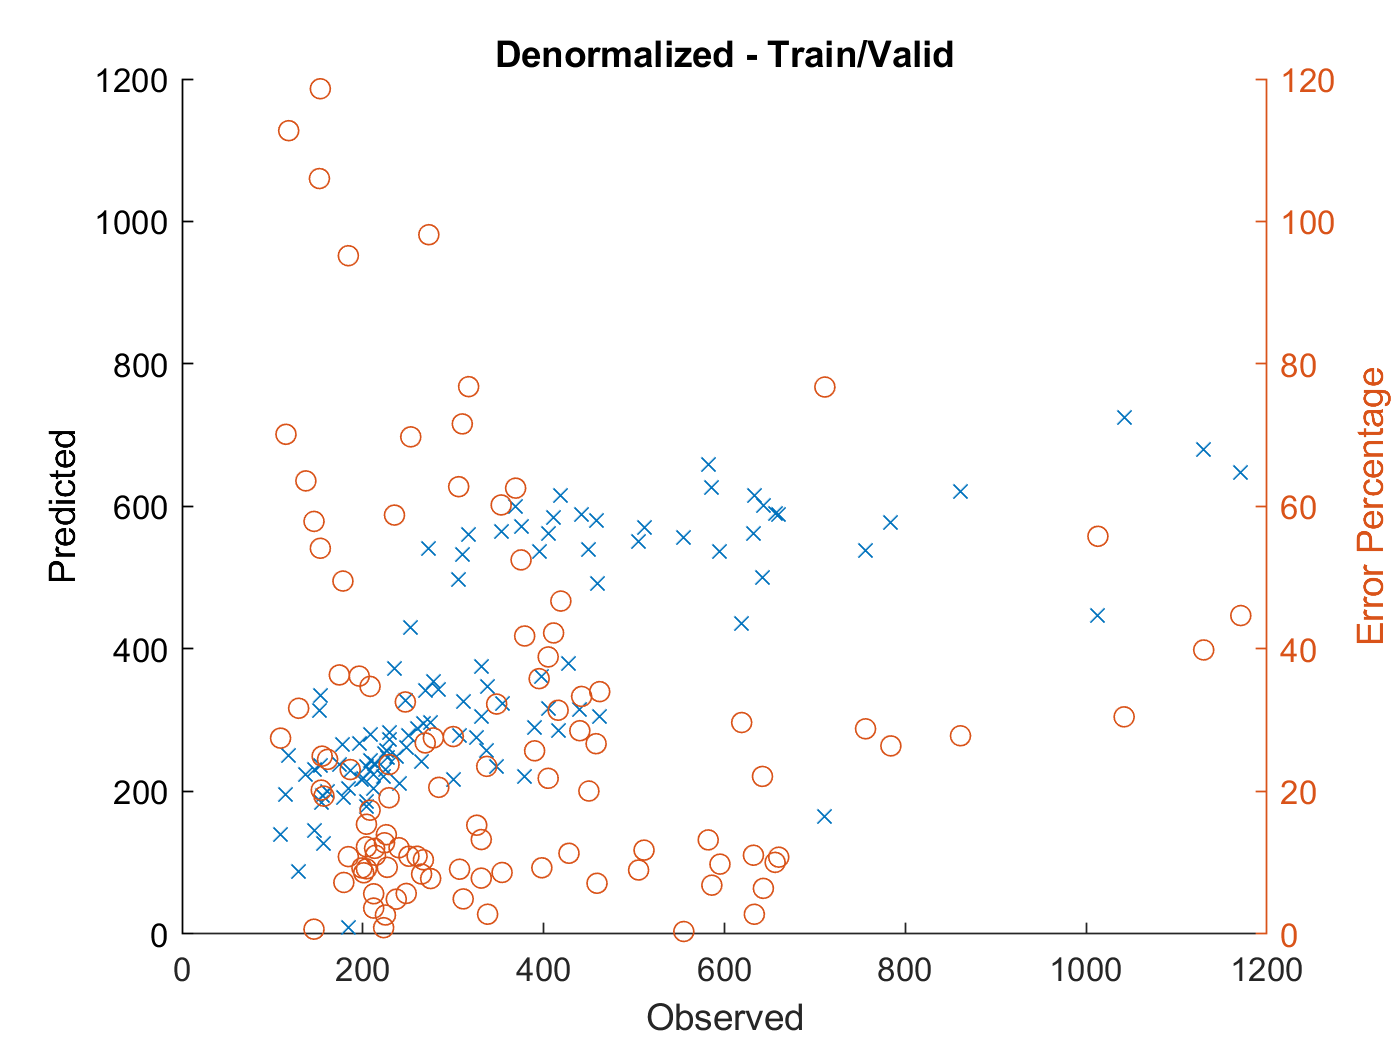

figure
hold on
plot(y_trainValid,yfit_trainValid,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(y_trainValid,y_trainValid_diff_percentage,'o');

hold off
title 'Denormalized - Train/Valid'

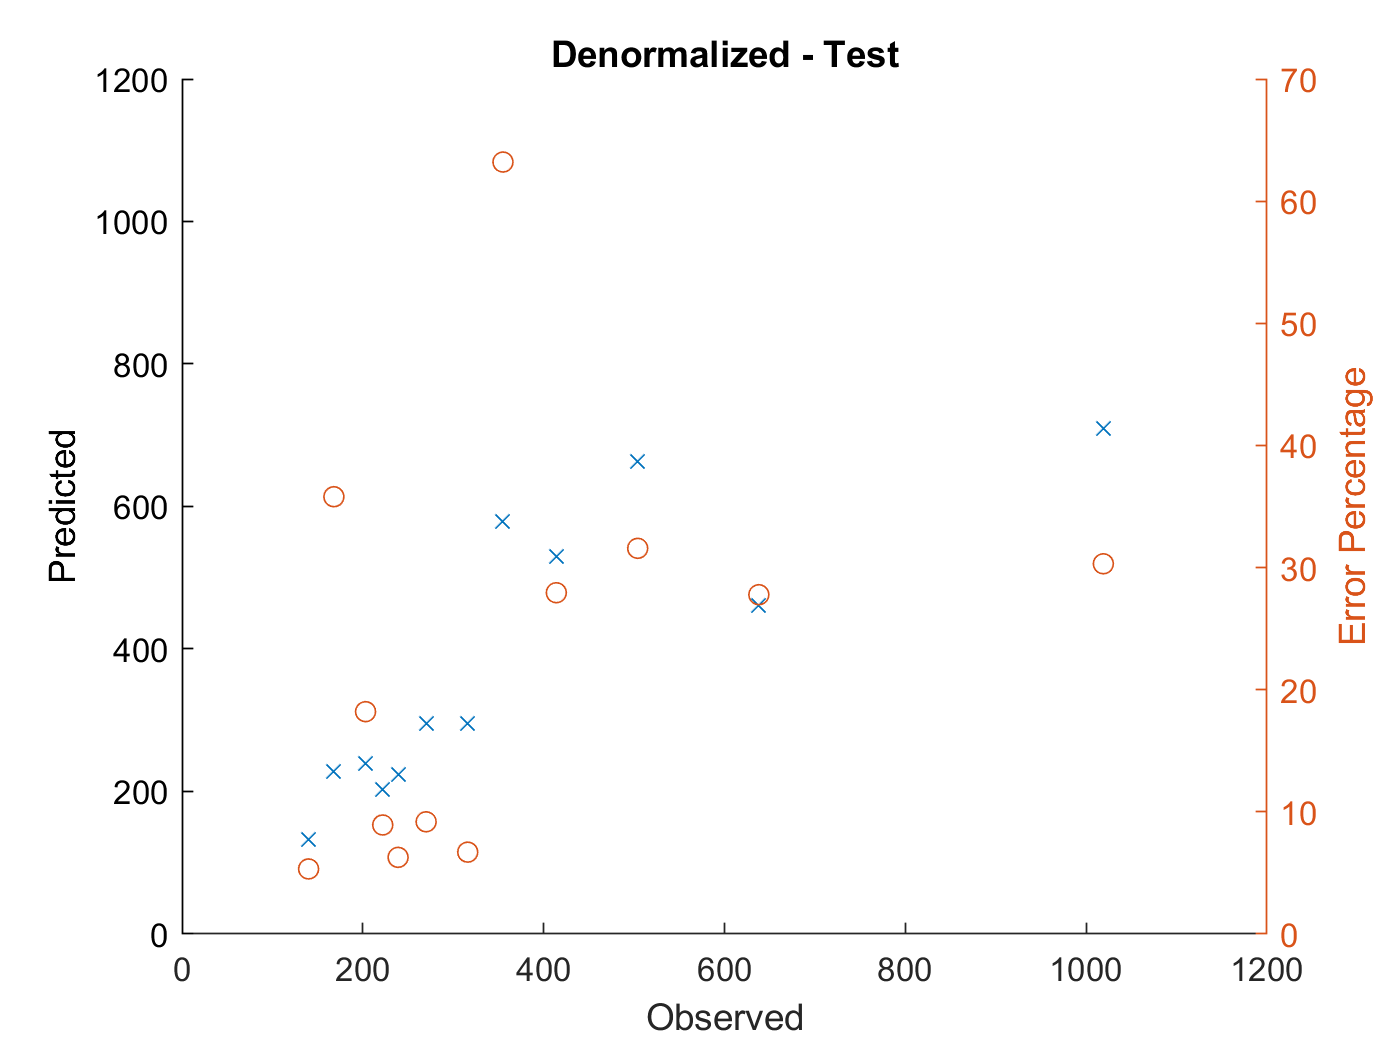


figure
hold on
plot(Y_test_IcFirst_RUL,yfit_test,'x')
xlabel("Observed")
ylabel("Predicted")
xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Y_test_IcFirst_RUL,y_test_diff_percentage,'o');

hold off
title 'Denormalized - Test'



% 테스트 셋에서는 예측이 전혀 안된다.


# FNN 학습 모델 생성

- netFNN1_1 = feedforwardnet(10);

- netFNN1_2 = feedforwardnet(20);

- netFNN1_3 = feedforwardnet(100);

- netFNN2_1 = feedforwardnet([20,20]);

- netFNN2_2 = feedforwardnet([100,20]);

- netFNN3_1 = feedforwardnet([20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20]);

- netFNN4_1 = feedforwardnet([20,20,20,20,20]);

- epoc = 300 

if generate_model
    

netFNN1_1 = feedforwardnet(10); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_1.divideFcn = 'divideind';
netFNN1_1.divideParam.trainInd = idxTrainRand;

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN1_1.divideParam.valInd = idxValidRand;
netFNN1_1.divideParam.testInd = idxTestRand; 
    
%netFNN1__1.divideParam
% https://kr.mathworks.com/matlabcentral/answers/314483-how-to-disable-popup-of-training-windows-for-neural-network-in-matlab
netFNN1_1.trainParam.showWindow = 0; 
netFNN1_1.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
[netFNN1_1, tr] = train(netFNN1_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%tr

netFNN1_2 = feedforwardnet(20); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_2.divideFcn = 'divideind';

netFNN1_2.divideFcn = 'divideind';

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN1_2.divideParam.trainInd = idxTrainRand;
netFNN1_2.divideParam.valInd = idxValidRand;
netFNN1_2.divideParam.testInd = idxTestRand; 
    
%netFNN1_2.divideParam
netFNN1_2.trainParam.showWindow = 0; 
netFNN1_2.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_2 = train(netFNN1_2, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');


netFNN1_3 = feedforwardnet(100); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN1_3.divideFcn = 'divideind';

netFNN1_3.divideFcn = 'divideind';

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN1_3.divideParam.trainInd = idxTrainRand;
netFNN1_3.divideParam.valInd = idxValidRand;
netFNN1_3.divideParam.testInd = idxTestRand; 
    
%netFNN1_3.divideParam
netFNN1_3.trainParam.showWindow = 0; 
netFNN1_3.trainParam.epochs = 300; % 전체 데이타를 300번 반복 이용해라
netFNN1_3 = train(netFNN1_3, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');


netFNN2_1 = feedforwardnet([20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN2_1.divideParam.trainInd = tr.trainInd;
netFNN2_1.divideParam.valInd = tr.valInd;
netFNN2_1.divideParam.testInd = tr.testInd; 

netFNN2_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_1.trainParam.showWindow = 0;
netFNN2_1.trainParam.show = NaN;
netFNN2_1 = train(netFNN2_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN2_2 = feedforwardnet([100,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
netFNN2_2.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN2_2.divideParam.trainInd = tr.trainInd;
netFNN2_2.divideParam.valInd = tr.valInd;
netFNN2_2.divideParam.testInd = tr.testInd; 

netFNN2_2.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN2_2.trainParam.show = NaN;
netFNN2_2.trainParam.showWindow = 0;
netFNN2_2 = train(netFNN2_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%view(netFNN2_1)
%netFNN2_1
%tr2

netFNN3_1 = feedforwardnet([20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN3_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN3_1.divideParam.trainInd = tr.trainInd;
netFNN3_1.divideParam.valInd = tr.valInd;
netFNN3_1.divideParam.testInd = tr.testInd; 

netFNN3_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN3_1.trainParam.show = NaN;
netFNN3_1.trainParam.showWindow = 0;
netFNN3_1 = train(netFNN3_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

netFNN4_1 = feedforwardnet([20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN4_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN4_1.divideParam.trainInd = tr.trainInd;
netFNN4_1.divideParam.valInd = tr.valInd;
netFNN4_1.divideParam.testInd = tr.testInd; 

netFNN4_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN4_1.trainParam.show = NaN;
netFNN4_1.trainParam.showWindow = 0;
netFNN4_1 = train(netFNN3_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

netFNN5_1 = feedforwardnet([20,20,20,20,20]); % 은익계층은 1개이며 이 크기는 10이다. defaut : 'trainlm' = Levenberg-Marquardt
% netFNN340.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

netFNN5_1.divideFcn = 'divideind'; % 'traingd' =	Gradient Descent

Cannot perform computations on a parallel pool.
Parallel Computing Toolbox license is not available.


netFNN5_1.divideParam.trainInd = tr.trainInd;
netFNN5_1.divideParam.valInd = tr.valInd;
netFNN5_1.divideParam.testInd = tr.testInd; 

netFNN5_1.trainParam.epochs = 300; %100; % 전체 데이타를 300번 반복 이용해라
netFNN5_1.trainParam.show = NaN;
netFNN5_1.trainParam.showWindow = 0;
netFNN5_1 = train(netFNN3_1, xnorm_IcFirst_RUL', ynorm_IcFirst_RUL', 'useparallel',  'yes');
%view(netFNN3_1)

save('ryan3_model_FirstCC_RUL.mat','netFNN1_1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN1_2' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN1_3' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN2_1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN2_2' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN3_1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN4_1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netFNN5_1' ,'-append')

end

# FNN 예측

pFNN1_1 = netFNN1_1(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN1_2 = netFNN1_2(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN1_3 = netFNN1_3(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN2_1 = netFNN2_1(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN2_2 = netFNN2_2(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN3_1 = netFNN3_1(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN4_1 = netFNN4_1(xnorm_IcFirst_RUL(idxTestSort, :)');
pFNN5_1 = netFNN5_1(xnorm_IcFirst_RUL(idxTestSort, :)');

ytest = ynorm_IcFirst_RUL(idxTestSort, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_1_hat = pFNN1_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_2_hat = pFNN1_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_3_hat = pFNN1_3 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_1_hat = 124.4565

pFNN2_1_hat = pFNN2_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_2_hat = 144.4811

pFNN2_2_hat = pFNN2_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_3_hat = 106.0541

pFNN3_1_hat = pFNN3_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN2_1_hat = 119.8410

pFNN4_1_hat = pFNN4_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN2_2_hat = 119.8410

pFNN5_1_hat = pFNN5_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN3_1_hat = 76.3414

rmse_pFNN4_1_hat = 76.3414

rmse_pFNN5_1_hat = 76.3414

rmse_pFNN1_1_hat = sqrt(mean(( ytest' - pFNN1_1_hat ).^2))

y_test_diff_percentage_FNN1_1_hat_avg = 28.5739

rmse_pFNN1_2_hat = sqrt(mean(( ytest' - pFNN1_2_hat ).^2))

y_test_diff_percentage_FNN1_2_hat_avg = 48.4665

rmse_pFNN1_3_hat = sqrt(mean(( ytest' - pFNN1_3_hat ).^2))

y_test_diff_percentage_FNN1_3_hat_avg = 41.3946

rmse_pFNN2_1_hat = sqrt(mean(( ytest' - pFNN2_1_hat ).^2))

y_test_diff_percentage_FNN2_1_hat_avg = 44.4607

rmse_pFNN2_2_hat = sqrt(mean(( ytest' - pFNN2_2_hat ).^2))

y_test_diff_percentage_FNN2_2_hat_avg = 44.4607

rmse_pFNN3_1_hat = sqrt(mean(( ytest' - pFNN3_1_hat ).^2))

y_test_diff_percentage_FNN3_1_hat_avg = 34.1795

rmse_pFNN4_1_hat = sqrt(mean(( ytest' - pFNN4_1_hat ).^2))

y_test_diff_percentage_FNN4_1_hat_avg = 34.1795

rmse_pFNN5_1_hat = sqrt(mean(( ytest' - pFNN5_1_hat ).^2))

y_test_diff_percentage_FNN5_1_hat_avg = 34.1795

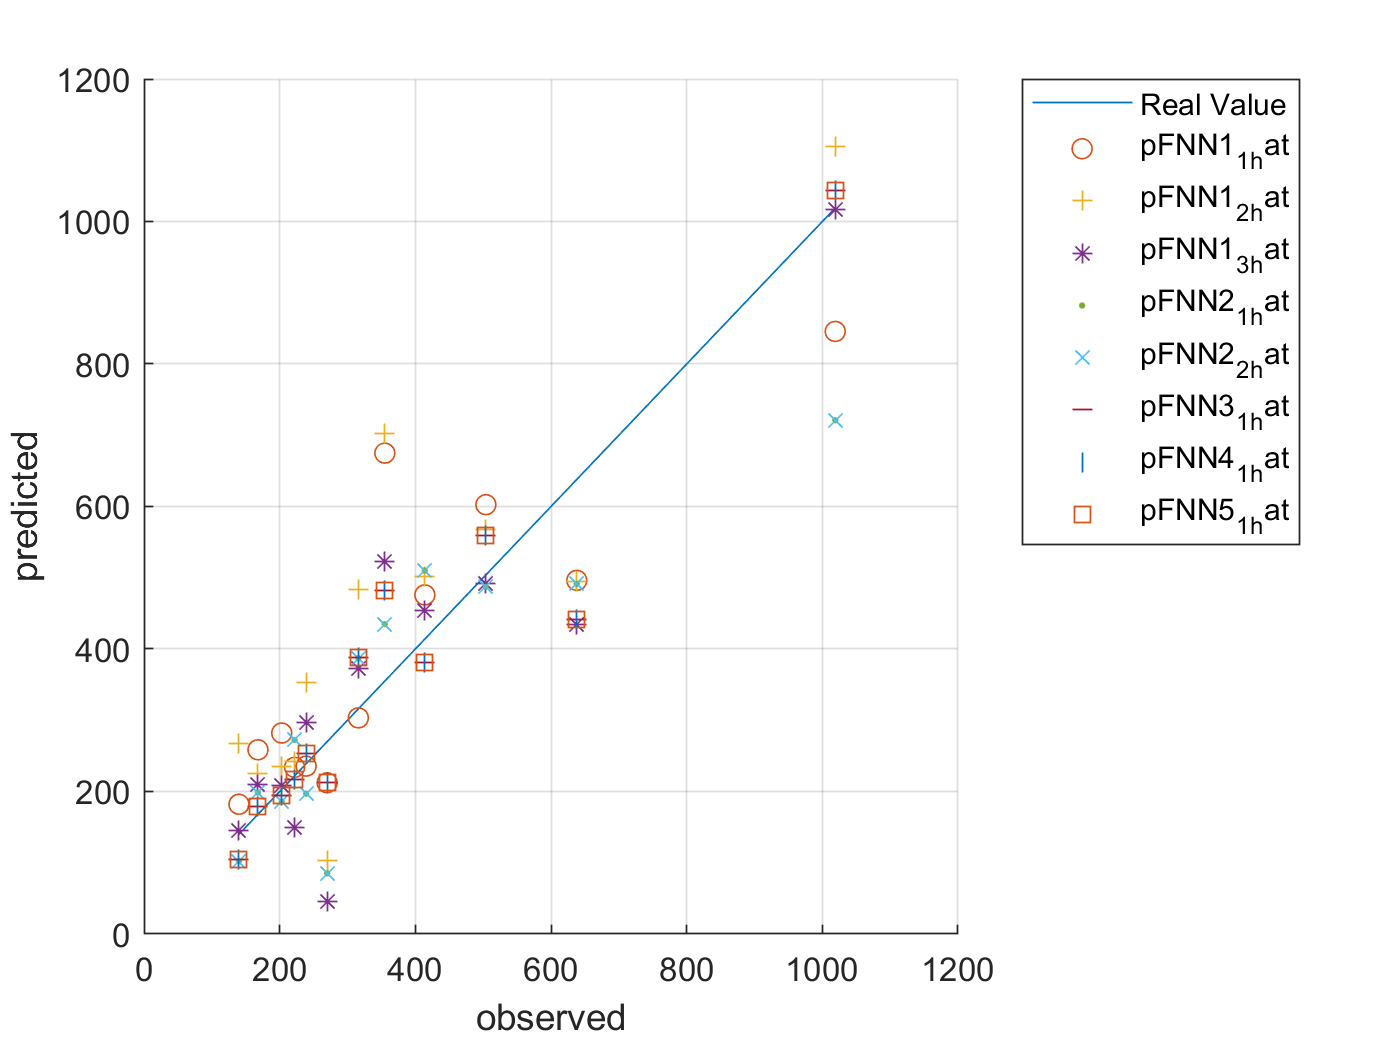

y_test_diff_percentage_FNN1_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN1_1_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN1_1_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN1_2_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN1_2_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN1_2_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN1_3_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN1_3_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN1_3_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN2_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN2_1_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN2_1_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN2_2_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN2_2_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN2_2_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN3_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN3_1_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN3_1_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN4_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN4_1_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN4_1_hat)./Y_test_IcFirst_RUL')
y_test_diff_percentage_FNN5_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pFNN5_1_hat)./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pFNN5_1_hat)./Y_test_IcFirst_RUL')


figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pFNN1_1_hat,'o')
plot(ytest,pFNN1_2_hat,'+')
plot(ytest,pFNN1_3_hat,'*')
plot(ytest,pFNN2_1_hat,'.')
plot(ytest,pFNN2_2_hat,'x')
plot(ytest,pFNN3_1_hat,'_')
plot(ytest,pFNN4_1_hat,'|')
plot(ytest,pFNN5_1_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 

		'pFNN1_1_hat', ... 
		'pFNN1_2_hat', ...
		'pFNN1_3_hat', ... 	
		'pFNN2_1_hat', ... 
		'pFNN2_2_hat', ... 
		'pFNN3_1_hat', ... 
		'pFNN4_1_hat', ... 
		'pFNN5_1_hat','Location','northeastoutside')

pFNN1_1_self = netFNN1_1(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN1_2_self = netFNN1_2(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN1_3_self = netFNN1_3(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN2_1_self = netFNN2_1(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN2_2_self = netFNN2_2(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN3_1_self = netFNN3_1(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN4_1_self = netFNN4_1(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');
pFNN5_1_self = netFNN5_1(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)');

ytrain_self = ynorm_IcFirst_RUL([idxTrainSort idxValidSort], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_1_self_hat = pFNN1_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_2_self_hat = pFNN1_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pFNN1_3_self_hat = pFNN1_3_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_1_self_hat = 130.3829

pFNN2_1_self_hat = pFNN2_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_2_self_hat = 150.6447

pFNN2_2_self_hat = pFNN2_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN1_3_self_hat = 100.4714

pFNN3_1_self_hat = pFNN3_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN2_1_self_hat = 127.4195

pFNN4_1_self_hat = pFNN4_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN2_2_self_hat = 127.4195

pFNN5_1_self_hat = pFNN5_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pFNN3_1_self_hat = 76.0977

rmse_pFNN4_1_self_hat = 76.0977

rmse_pFNN5_1_self_hat = 76.0977

rmse_pFNN1_1_self_hat = sqrt(mean(( ytrain_self' - pFNN1_1_self_hat ).^2))

y_test_diff_percentage_FNN1_1_self_hat_avg = 0.2310

rmse_pFNN1_2_self_hat = sqrt(mean(( ytrain_self' - pFNN1_2_self_hat ).^2))

ytrain_self_diff_percentage_FNN1_2_self_hat_avg = 0.2994

rmse_pFNN1_3_self_hat = sqrt(mean(( ytrain_self' - pFNN1_3_self_hat ).^2))

ytrain_self_diff_percentage_FNN1_3_self_hat_avg = 0.1308

rmse_pFNN2_1_self_hat = sqrt(mean(( ytrain_self' - pFNN2_1_self_hat ).^2))

ytrain_self_diff_percentage_FNN2_1_self_hat_avg = 0.2681

rmse_pFNN2_2_self_hat = sqrt(mean(( ytrain_self' - pFNN2_2_self_hat ).^2))

ytrain_self_diff_percentage_FNN2_2_self_hat_avg = 0.2681

rmse_pFNN3_1_self_hat = sqrt(mean(( ytrain_self' - pFNN3_1_self_hat ).^2))

ytrain_self_diff_percentage_FNN3_1_self_hat_avg = 0.1156

rmse_pFNN4_1_self_hat = sqrt(mean(( ytrain_self' - pFNN4_1_self_hat ).^2))

ytrain_self_diff_percentage_FNN4_1_self_hat_avg = 0.1156

rmse_pFNN5_1_self_hat = sqrt(mean(( ytrain_self' - pFNN5_1_self_hat ).^2))

ytrain_self_diff_percentage_FNN5_1_self_hat_avg = 0.1156

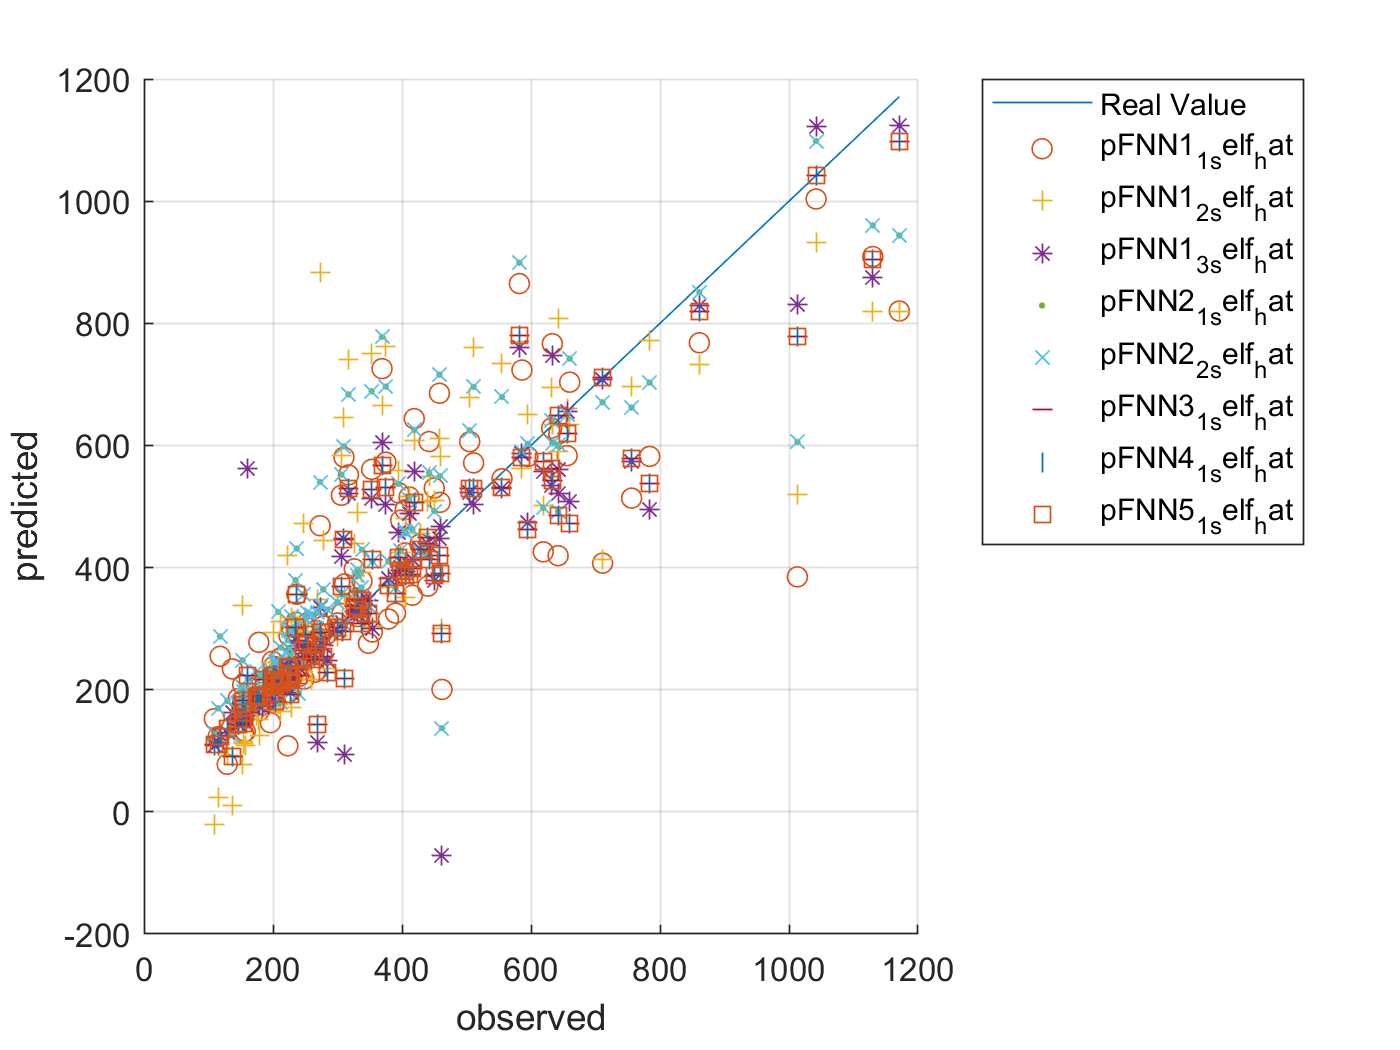

y_test_diff_percentage_FNN1_1_self_hat_avg = sum(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_1_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN1_2_self_hat_avg = sum(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_2_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN1_3_self_hat_avg = sum(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN1_3_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN2_1_self_hat_avg = sum(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN2_1_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN2_2_self_hat_avg = sum(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN2_2_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN3_1_self_hat_avg = sum(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN3_1_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN4_1_self_hat_avg = sum(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN4_1_self_hat)./ytrain_self')
ytrain_self_diff_percentage_FNN5_1_self_hat_avg = sum(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self'.*100)/length(abs(ytrain_self'-pFNN5_1_self_hat)./ytrain_self')



figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pFNN1_1_self_hat,'o')
plot(ytrain_self,pFNN1_2_self_hat,'+')
plot(ytrain_self,pFNN1_3_self_hat,'*')
plot(ytrain_self,pFNN2_1_self_hat,'.')
plot(ytrain_self,pFNN2_2_self_hat,'x')
plot(ytrain_self,pFNN3_1_self_hat,'_')
plot(ytrain_self,pFNN4_1_self_hat,'|')
plot(ytrain_self,pFNN5_1_self_hat,'s')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 

		'pFNN1_1_self_hat', ... 
		'pFNN1_2_self_hat', ...
		'pFNN1_3_self_hat', ... 	
		'pFNN2_1_self_hat', ... 
		'pFNN2_2_self_hat', ... 
		'pFNN3_1_self_hat', ... 
		'pFNN4_1_self_hat', ... 
		'pFNN5_1_self_hat','Location','northeastoutside')

# CNN 모델 생성

filterSize = 3;
numFilters = 32;
numFCN = 1;
cc_input_size = 20;

- CNN1 : 2 Convolution Layer with filter size [1, 2] and number of filter 10, 5.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:34 |         0.32 |         0.29 |       0.0506 |       0.0416 |          0.0010 |
|      50 |          50 |       00:00:47 |         0.22 |         0.23 |       0.0249 |       0.0256 |          0.0010 |
|     100 |         100 |       00:00:53 |         0.20 |         0.23 |       0.0203 |       0.0256 |          0.0010 |
|     150 |         150 |       00:00:58 |         0.18 |         0.22 |       0.0159 |   

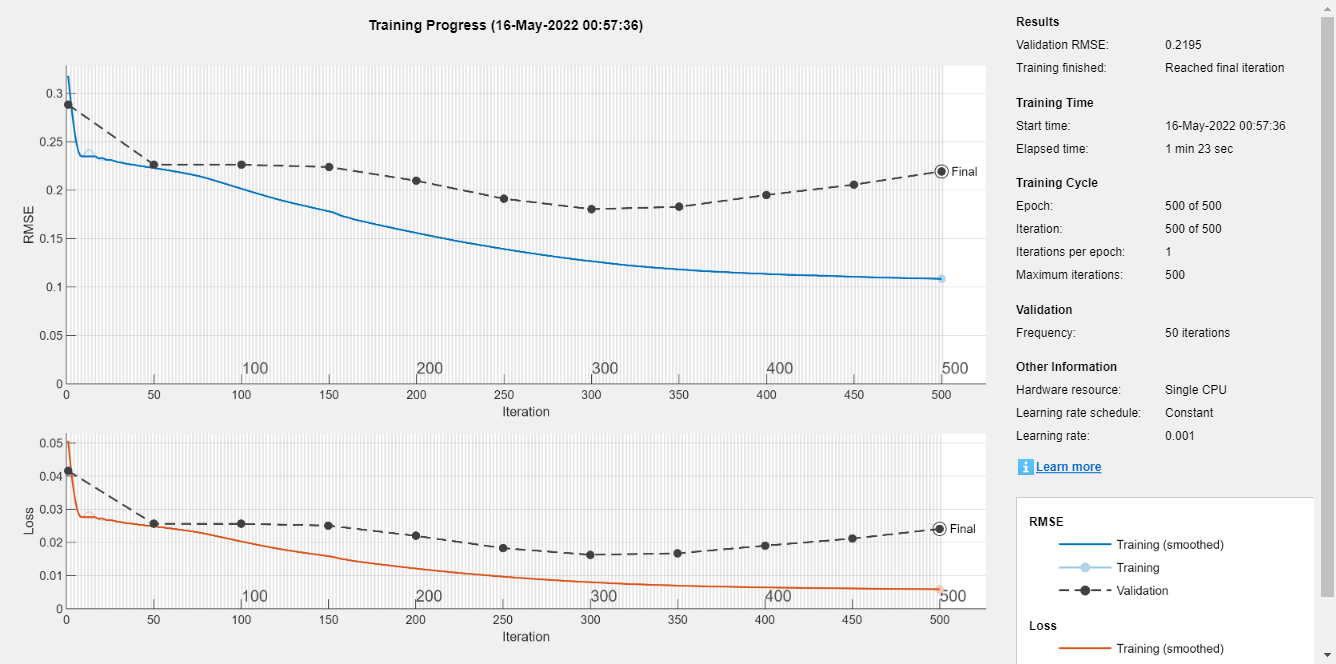

if generate_model

layerCNN2_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];
cellx = num2cell(xnorm_IcFirst_RUL', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);
cellyB = num2cell(ynorm_IcFirst_RUL);
tbl = table(cellx);
tbl.cellyB = cellyB;


Traintbl = tbl(tr.trainInd, :);
valtbl = tbl(tr.valInd, :);
testtbl = tbl(tr.testInd, :);


options = trainingOptions('adam', ...
 'InitialLearnRate', 0.001, ...
 'MaxEpochs',500, ...
 'MiniBatchSize',50, ...
 'Plots','training-progress', 'ValidationData', valtbl);

netCNN2_1 = trainNetwork(Traintbl, layerCNN2_1, options);




- CNN2 :2 Convolution Layer with filter size [1, 2] and number of filter 30, 15.

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |         0.33 |         0.32 |       0.0544 |       0.0516 |          0.0010 |
|      50 |          50 |       00:00:24 |         0.20 |         0.23 |       0.0205 |       0.0254 |          0.0010 |
|     100 |         100 |       00:00:30 |         0.19 |         0.22 |       0.0174 |       0.0246 |          0.0010 |
|     150 |         150 |       00:00:35 |         0.17 |         0.21 |       0.0150 |   

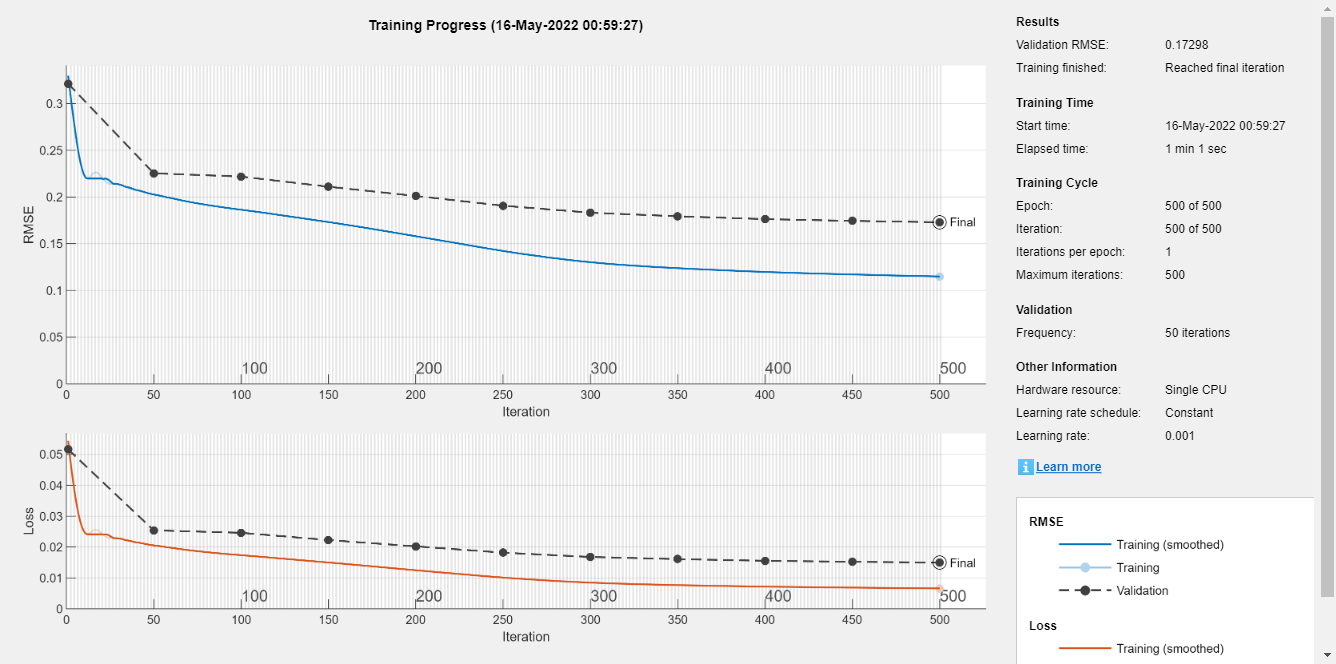

layerCNN2_2 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:20 |         0.34 |         0.31 |       0.0591 |       0.0469 |          0.0010 |
|      50 |          50 |       00:00:29 |         0.23 |         0.23 |       0.0267 |       0.0255 |          0.0010 |
|     100 |         100 |       00:00:35 |         0.22 |         0.23 |       0.0246 |       0.0262 |          0.0010 |
|     150 |         150 |       00:00:41 |         0.21 |         0.23 |       0.0229 |   

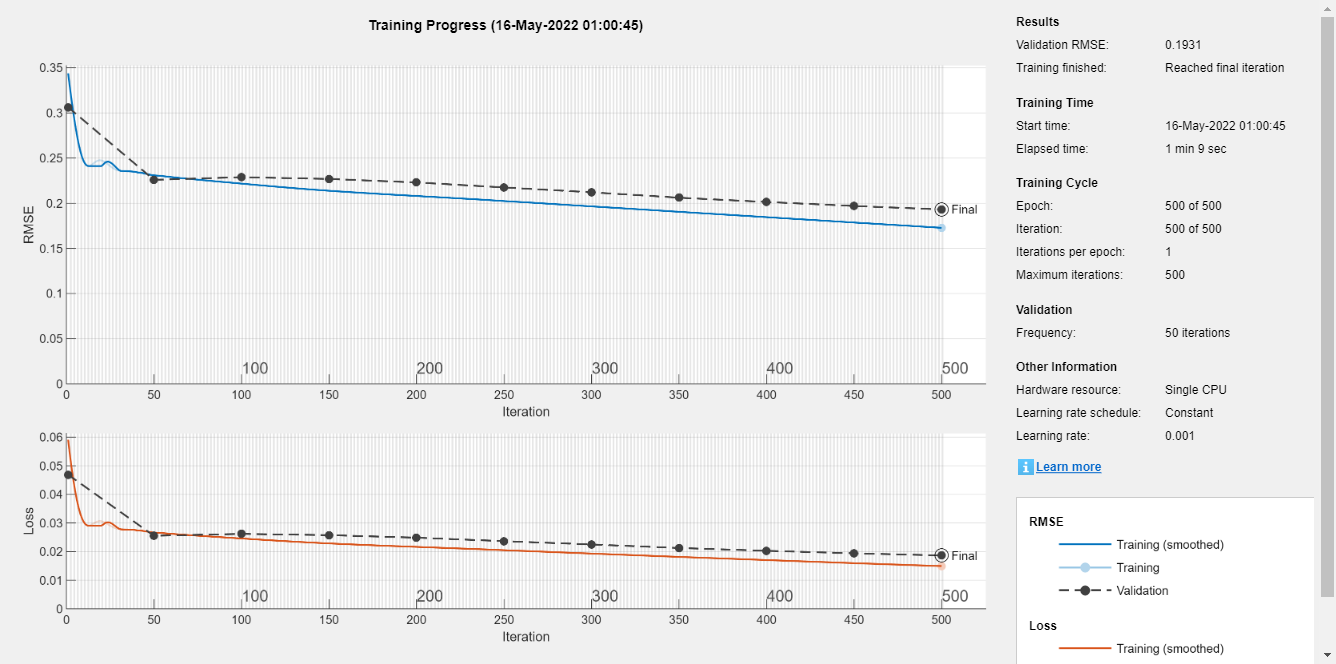

    leakyReluLayer
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

netCNN2_2 = trainNetwork(Traintbl, layerCNN2_1, options);

layerCNN1_1 = [
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    leakyReluLayer
    fullyConnectedLayer(numFCN)
    regressionLayer();
    ];

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:11 |         0.22 |         0.42 |       0.0232 |       0.0890 |          0.0010 |
|      50 |          50 |       00:00:21 |         0.18 |         0.25 |       0.0154 |       0.0302 |          0.0010 |
|     100 |         100 |       00:00:27 |         0.16 |         0.24 |       0.0135 |       0.0285 |          0.0010 |
|     150 |         150 |       00:00:34 |         0.15 |         0.23 |       0.0118 |   

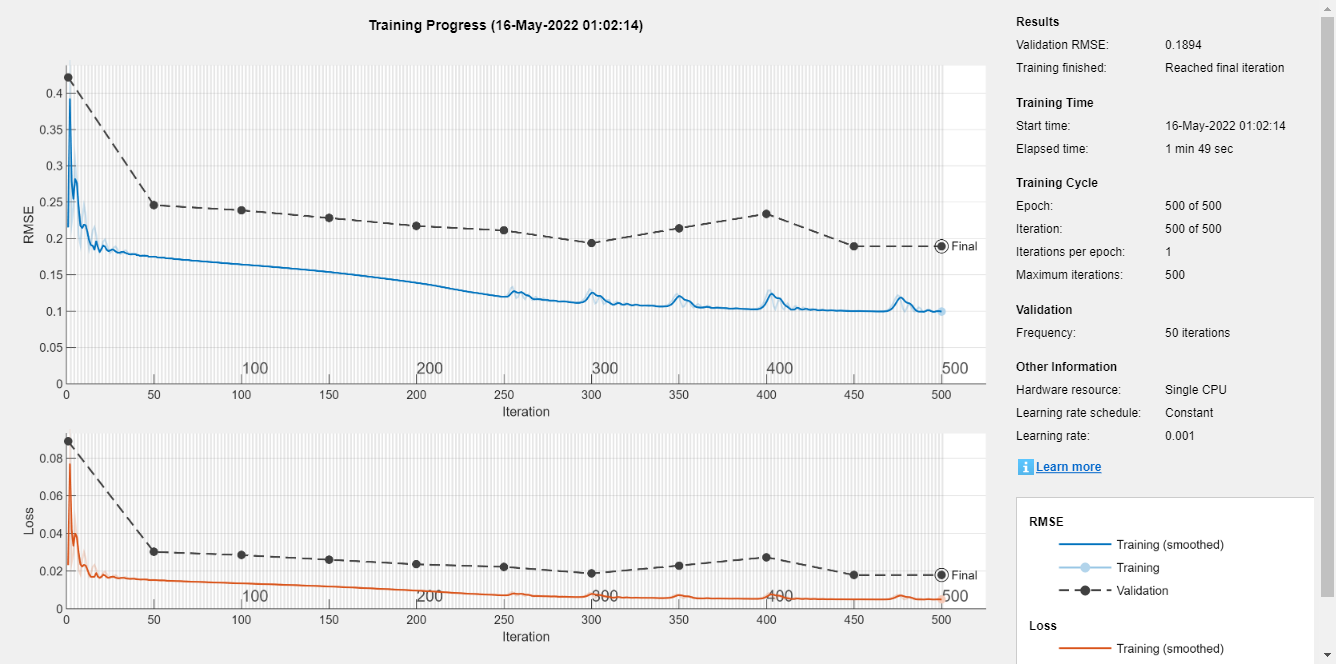

%     sequenceInputLayer(input_size)
%     convolution1dLayer(filterSize,numFilters)
%     reluLayer
%     globalMaxPooling1dLayer
%     fullyConnectedLayer(numFCN)
%     %softmaxLayer
%     regressionLayer();]
netCNN1_1 = trainNetwork(Traintbl, layerCNN1_1, options);


layerCNN2_3 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:26 |         0.51 |         2.47 |       0.1291 |       3.0555 |          0.0010 |
|      50 |          50 |       00:00:58 |         0.22 |         0.24 |       0.0232 |       0.0294 |          0.0010 |
|     100 |         100 |       00:01:21 |         0.20 |         0.24 |       0.0197 |       0.0299 |          0.0010 |
|     150 |         150 |       00:01:31 |         0.19 |         0.24 |       0.0187 |   

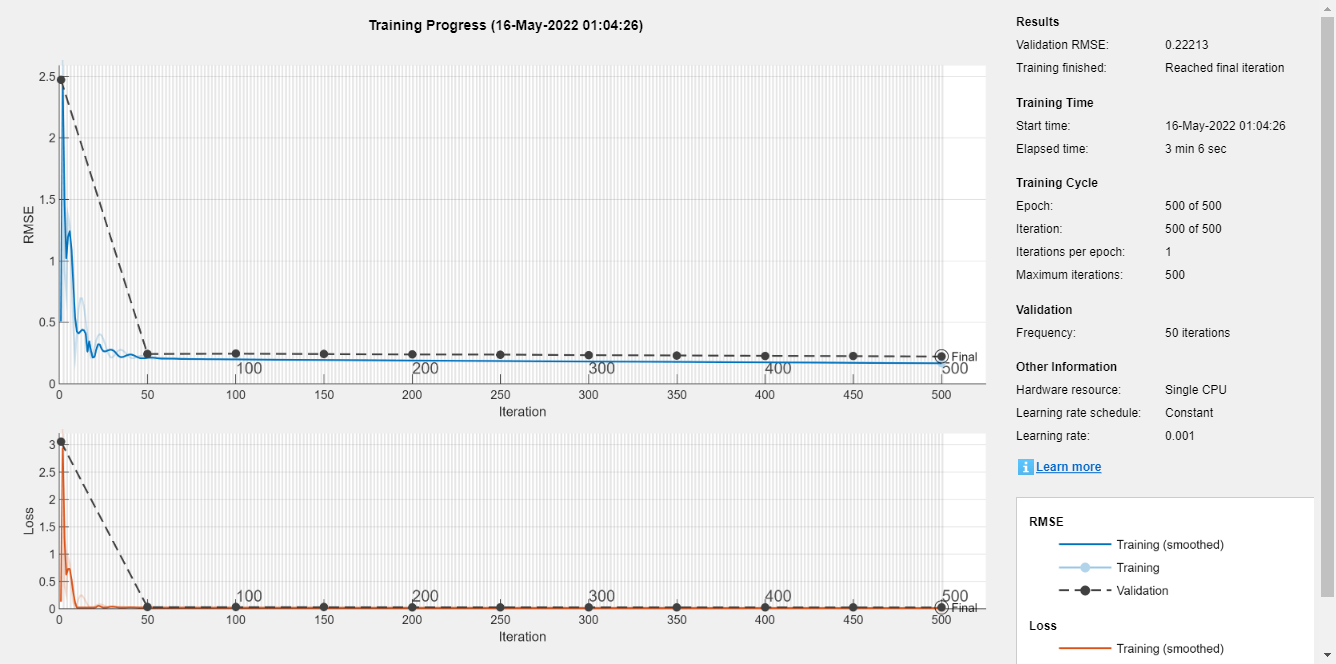

    convolution2dLayer([1, filterSize], numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_3 = trainNetwork(Traintbl, layerCNN2_3, options);

layerCNN2_4 = [ ...
    imageInputLayer([1, cc_input_size]);
    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
     reluLayer
    layerNormalizationLayer

    convolution2dLayer([1, 2*filterSize], 2*numFilters, 'Stride', 1);
    reluLayer
    layerNormalizationLayer
    globalAveragePooling2dLayer
    fullyConnectedLayer(numFCN)
    %softmaxLayer
    regressionLayer();];
netCNN2_4 = trainNetwork(Traintbl, layerCNN2_4, options);

save('ryan3_model_FirstCC_RUL.mat','netCNN2_1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netCNN2_2' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netCNN2_3' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netCNN2_4' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netCNN1_1' ,'-append')

end

# CNN 예측

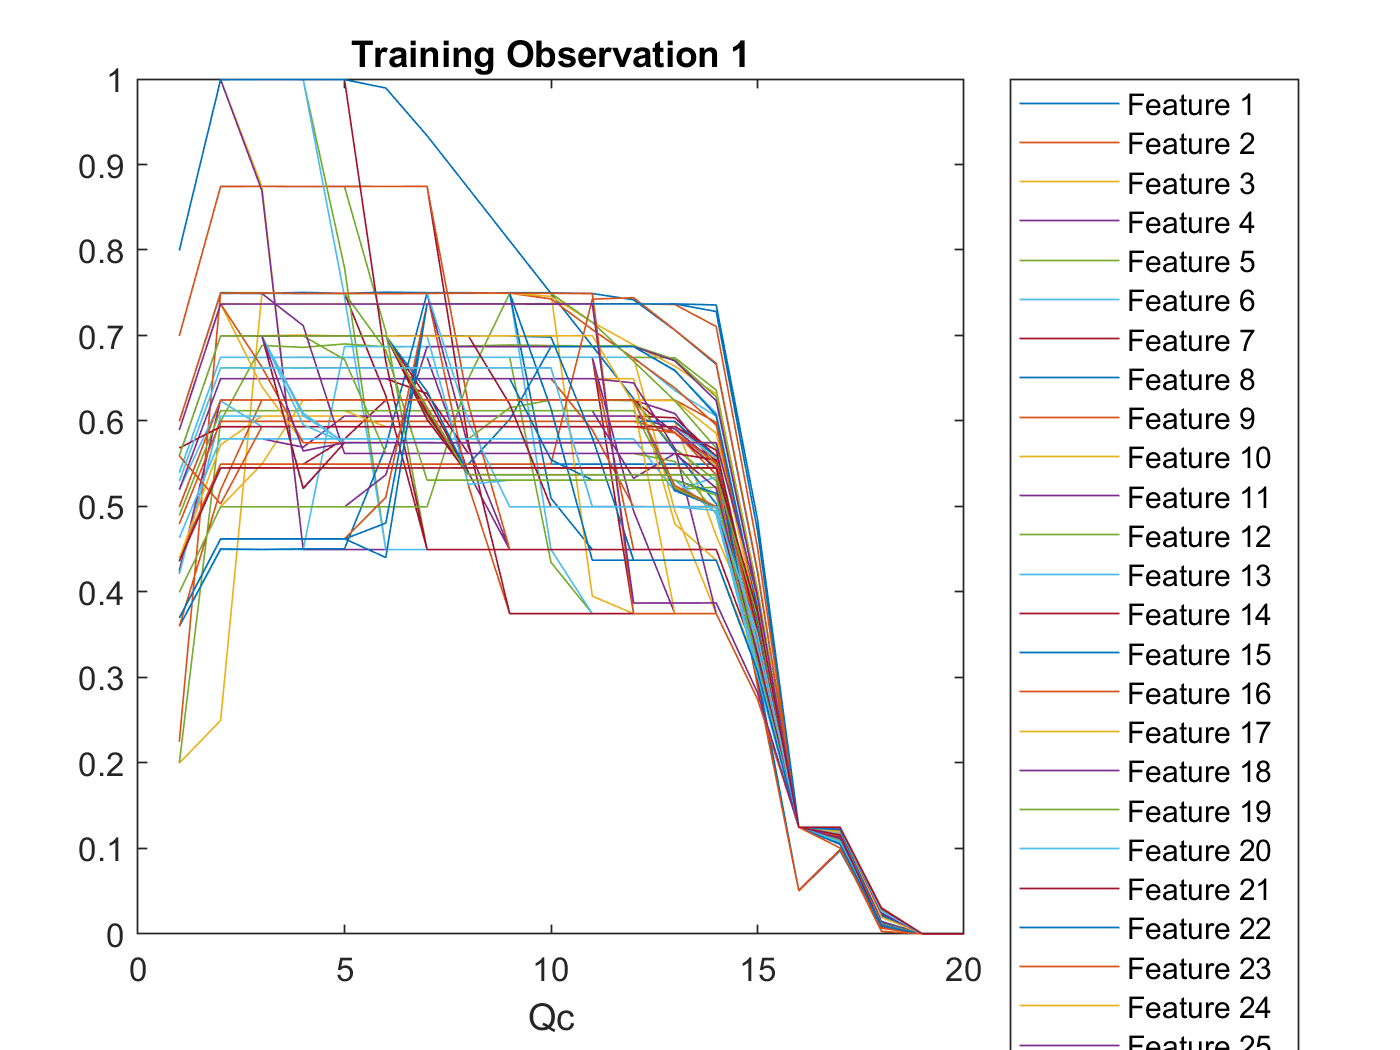

filterSize = 3;
numFilters = 32;
numFCN = 1;

cc_input_size = 20;

figure
plot(xnorm_IcFirst_RUL')
xlabel("Qc")
title("Training Observation 1")
numFeatures = size(xnorm_IcFirst_RUL,1);
legend("Feature " + string(1:numFeatures),Location="northeastoutside")


cellx = num2cell(xnorm_IcFirst_RUL(idxTestSort, :)', 1)';
cellx = cellfun(@transpose, cellx, 'UniformOutput', false);

pCNN2_1 = 12×1 single column vector
    0.1895
    0.0914
    0.1020
    0.3731
    0.0472
    0.0740
   -0.0190
    0.3366
    0.3248
    0.4823


tbl = table(cellx);

pCNN2_2 = 12×1 single column vector
    0.1764
    0.1086
    0.1127
    0.3547
    0.0808
    0.0996
    0.0032
    0.3613
    0.3351
    0.5279


pCNN2_3 = 12×1 single column vector
   -0.0098
    0.1435
    0.0308
    0.0907
    0.0169
    0.1380
   -0.0029
    0.3926
    0.3870
    0.4506


x_4d = zeros(1, cc_input_size, 1, height(tbl));

pCNN2_4 = 12×1 single column vector
   -0.0037
    0.1243
   -0.0217
    0.3080
    0.2136
    0.2668
    0.1024
    0.3236
    0.3397
    0.3210


for i = 1:height(tbl)

pCNN1_1 = 12×1 single column vector
    0.1835
    0.1048
    0.1308
    0.3899
    0.1888
    0.1913
    0.1461
    0.3163
    0.4104
    0.3256


    x_4d(:,:,:,i) = tbl.cellx{i};
end

pCNN2_1 = predict(netCNN2_1, x_4d)
pCNN2_2 = predict(netCNN2_2, x_4d)
pCNN2_3 = predict(netCNN2_3, x_4d)
pCNN2_4 = predict(netCNN2_4, x_4d)
pCNN1_1 = predict(netCNN1_1, x_4d)



ytest = ynorm_IcFirst_RUL(idxTestSort, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_1_hat = single
198.5319

pCNN2_1_hat = pCNN2_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_2_hat = single
140.4942

pCNN2_2_hat = pCNN2_2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_3_hat = single
139.7862

pCNN2_3_hat = pCNN2_3 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_4_hat = single
171.6500

pCNN2_4_hat = pCNN2_4 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN1_1_hat = single
144.4768

pCNN1_1_hat = pCNN1_1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

y_test_diff_percentage_CNN2_1_hat_avg = single
45.8475

y_test_diff_percentage_CNN2_2_hat_avg = single
40.7081

y_test_diff_percentage_CNN2_3_hat_avg = single
33.7986

rmse_pCNN2_1_hat = sqrt(mean(( ytest' - pCNN2_1_hat' ).^2))

y_test_diff_percentage_CNN2_4_hat_avg = single
38.5942

rmse_pCNN2_2_hat = sqrt(mean(( ytest' - pCNN2_2_hat' ).^2))

y_test_diff_percentage_CNN1_1_hat_avg = single
39.3921

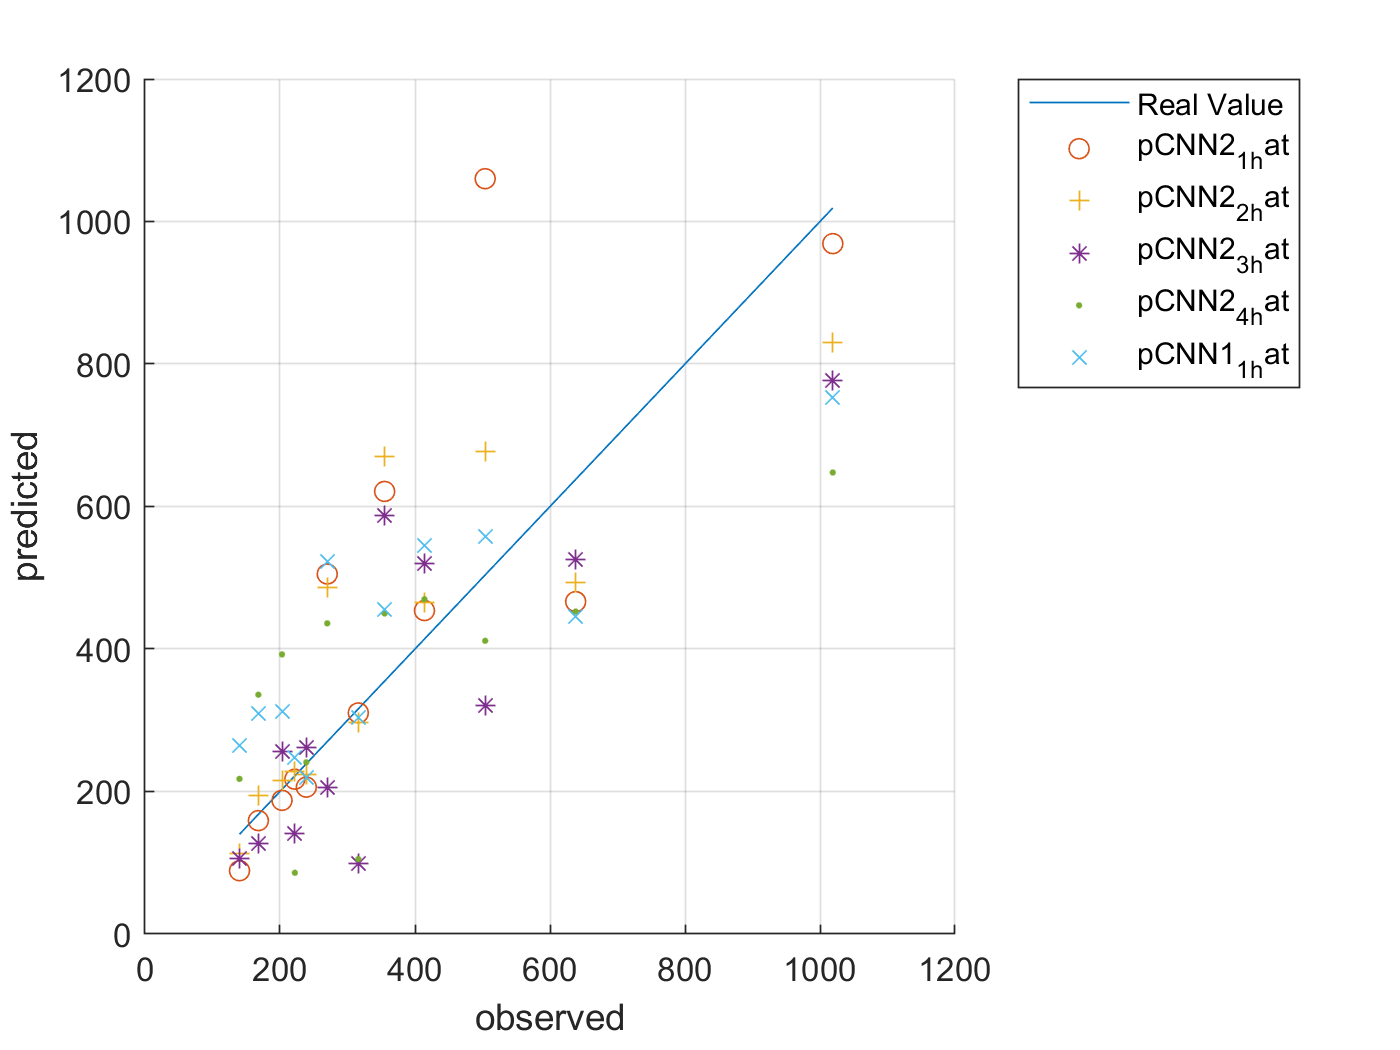

rmse_pCNN2_3_hat = sqrt(mean(( ytest' - pCNN2_3_hat' ).^2))
rmse_pCNN2_4_hat = sqrt(mean(( ytest' - pCNN2_4_hat' ).^2))
rmse_pCNN1_1_hat = sqrt(mean(( ytest' - pCNN1_1_hat' ).^2))
y_test_diff_percentage_CNN2_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pCNN2_1_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pCNN2_1_hat')./Y_test_IcFirst_RUL')
y_test_diff_percentage_CNN2_2_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pCNN2_2_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pCNN2_2_hat')./Y_test_IcFirst_RUL')
y_test_diff_percentage_CNN2_3_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pCNN2_3_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pCNN2_3_hat')./Y_test_IcFirst_RUL')
y_test_diff_percentage_CNN2_4_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pCNN2_4_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pCNN2_4_hat')./Y_test_IcFirst_RUL')
y_test_diff_percentage_CNN1_1_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pCNN1_1_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pCNN1_1_hat')./Y_test_IcFirst_RUL')



figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pCNN2_1_hat,'o')
plot(ytest,pCNN2_2_hat,'+')
plot(ytest,pCNN2_3_hat,'*')
plot(ytest,pCNN2_4_hat,'.')
plot(ytest,pCNN1_1_hat,'x')

hold off


xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_hat', ... 
		'pCNN2_2_hat', ...
		'pCNN2_3_hat', ... 	
		'pCNN2_4_hat', ... 
		'pCNN1_1_hat','Location','northeastoutside')




cellx_self = num2cell(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)', 1)';
cellx_self = cellfun(@transpose, cellx_self, 'UniformOutput', false);
tbl_self = table(cellx_self);

x_4d_self = zeros(1, cc_input_size, 1, height(tbl_self));
for i = 1:height(tbl_self)
    x_4d_self(:,:,:,i) = tbl_self.cellx_self{i};
end

pCNN2_1_self = predict(netCNN2_1, x_4d_self);
pCNN2_2_self = predict(netCNN2_2, x_4d_self);
pCNN2_3_self = predict(netCNN2_3, x_4d_self);
pCNN2_4_self = predict(netCNN2_4, x_4d_self);
pCNN1_1_self = predict(netCNN1_1, x_4d_self);

ytrain_self = ynorm_IcFirst_RUL([idxTrainSort idxValidSort], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pCNN2_1_self_hat = pCNN2_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_1_self_hat = single
161.4963

pCNN2_2_self_hat = pCNN2_2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_2_self_hat = single
144.8524

pCNN2_3_self_hat = pCNN2_3_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_3_self_hat = single
153.5587

pCNN2_4_self_hat = pCNN2_4_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN2_4_self_hat = single
184.0321

pCNN1_1_self_hat = pCNN1_1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;

rmse_pCNN1_1_self_hat = single
175.4604

ytrain_self_diff_percentage_CNN2_1_self_hat_avg = single
32.4418

ytrain_self_diff_percentage_CNN2_2_self_hat_avg = single
30.3555

ytrain_self_diff_percentage_CNN2_3_self_hat_avg = single
29.8865

rmse_pCNN2_1_self_hat = sqrt(mean(( ytrain_self' - pCNN2_1_self_hat' ).^2))

ytrain_self_diff_percentage_CNN2_4_self_hat_avg = single
46.1979

rmse_pCNN2_2_self_hat = sqrt(mean(( ytrain_self' - pCNN2_2_self_hat' ).^2))

ytrain_self_diff_percentage_CNN1_1_self_hat_avg = single
45.2318

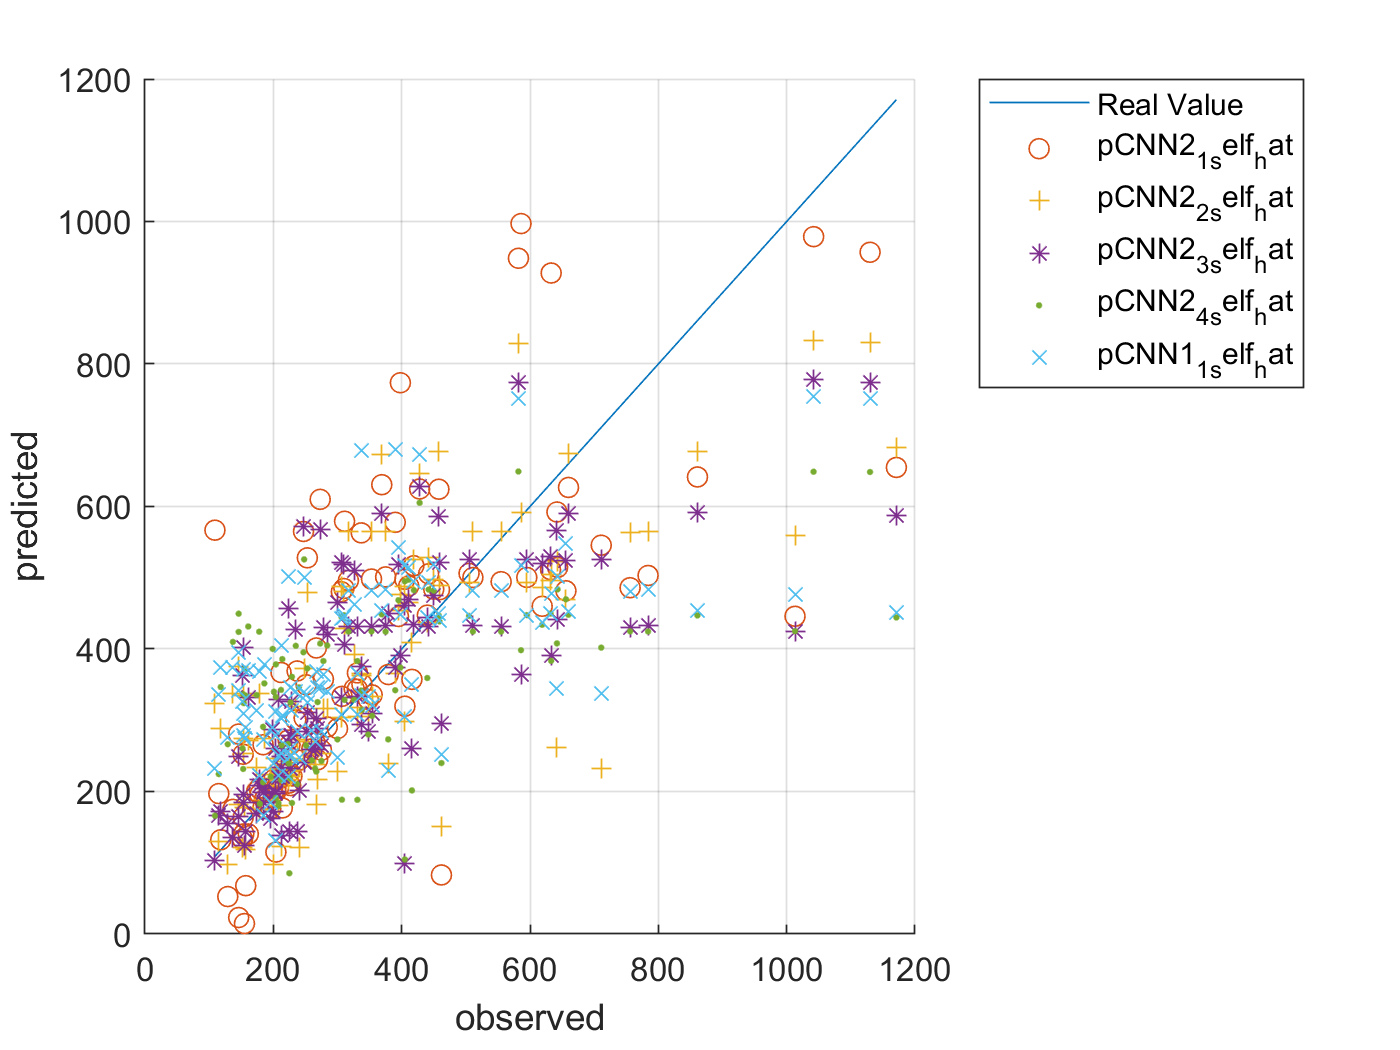

rmse_pCNN2_3_self_hat = sqrt(mean(( ytrain_self' - pCNN2_3_self_hat' ).^2))
rmse_pCNN2_4_self_hat = sqrt(mean(( ytrain_self' - pCNN2_4_self_hat' ).^2))
rmse_pCNN1_1_self_hat = sqrt(mean(( ytrain_self' - pCNN1_1_self_hat' ).^2))
ytrain_self_diff_percentage_CNN2_1_self_hat_avg = sum(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_1_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN2_2_self_hat_avg = sum(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_2_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN2_3_self_hat_avg = sum(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_3_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN2_4_self_hat_avg = sum(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN2_4_self_hat')./ytrain_self')
ytrain_self_diff_percentage_CNN1_1_self_hat_avg = sum(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self'.*100)/length(abs(ytrain_self'-pCNN1_1_self_hat')./ytrain_self')


figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pCNN2_1_self_hat,'o')
plot(ytrain_self,pCNN2_2_self_hat,'+')
plot(ytrain_self,pCNN2_3_self_hat,'*')
plot(ytrain_self,pCNN2_4_self_hat,'.')
plot(ytrain_self,pCNN1_1_self_hat,'x')

hold off


xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pCNN2_1_self_hat', ... 
		'pCNN2_2_self_hat', ...
		'pCNN2_3_self_hat', ... 	
		'pCNN2_4_self_hat', ... 
		'pCNN1_1_self_hat','Location','northeastoutside')



# LSTM 모델 생성

- LSTM : 1 lstm layer with 5 hidden units

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:13 |         0.26 |         0.28 |       0.0346 |       0.0397 |          0.0010 |
|      50 |          50 |       00:00:20 |         0.19 |         0.22 |       0.0186 |       0.0249 |          0.0010 |
|     100 |         100 |       00:00:24 |         0.19 |         0.22 |       0.0179 |       0.0243 |          0.0010 |
|     150 |         150 |       00:00:30 |         0.19 |         0.22 |       0.0172 |       0.0239 |          0.0010 |
|     20

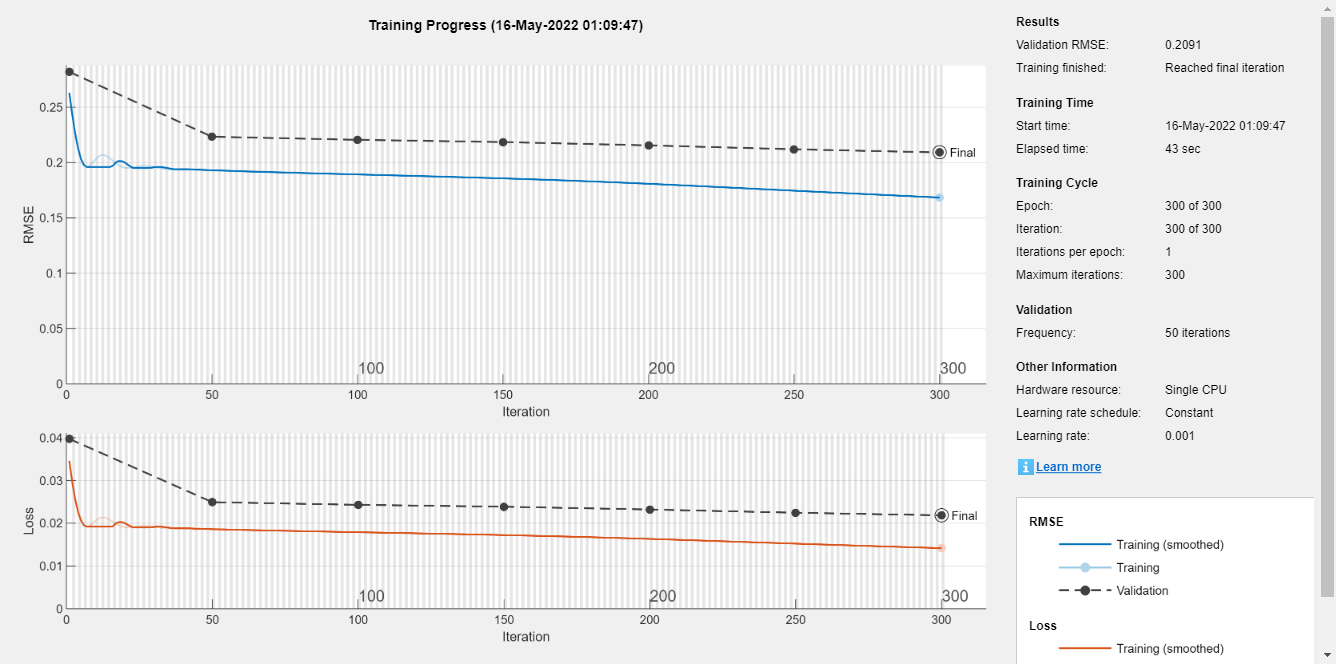

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:12 |         0.31 |         0.32 |       0.0469 |       0.0497 |          0.0010 |
|      50 |          50 |       00:00:25 |         0.22 |         0.22 |       0.0240 |       0.0252 |          0.0010 |
|     100 |         100 |       00:00:35 |         0.21 |         0.22 |       0.0219 |       0.0248 |          0.0010 |
|     150 |         150 |       00:00:40 |         0.20 |         0.22 |       0.0202 |       0.0250 |          0.0010 |
|     20

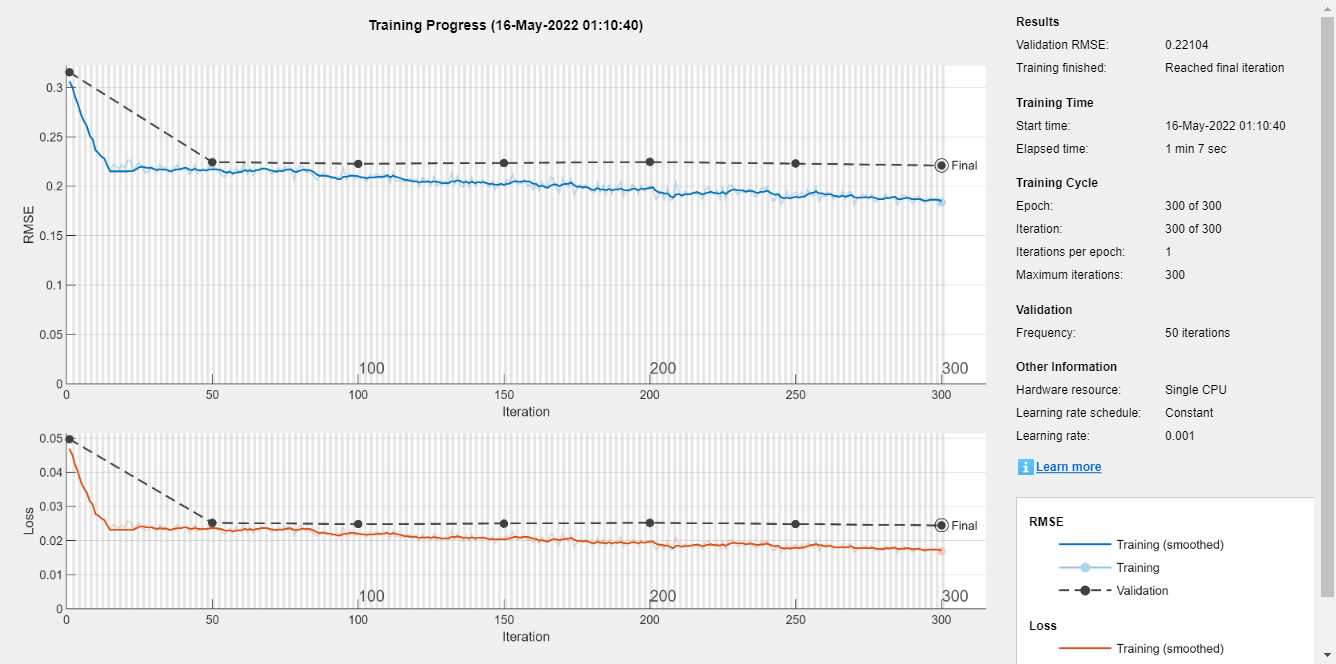

cc_input_size = 20;
numHiddenUnits = 50;

if generate_model
    
layersLSTM1 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    fullyConnectedLayer(1)
    regressionLayer
    ];

layersLSTM2 = [ ...
    sequenceInputLayer(cc_input_size)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    lstmLayer(numHiddenUnits)
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer
    ];

cellx = num2cell(xnorm_IcFirst_RUL', 1)';
cellyB = num2cell(ynorm_IcFirst_RUL);

traincellx = cellx(tr.trainInd, :);
valcellx = cellx(tr.valInd, :);
testcellx = cellx(tr.testInd, :);

traincellyB = cellyB(tr.trainInd, :);
valcellyB = cellyB(tr.valInd, :);
testcellyB = cellyB(tr.testInd, :);

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...
    'MaxEpochs',300, ...
    'MiniBatchSize',50, ...
    'Plots','training-progress', 'ValidationData', {valcellx, valcellyB});

netLSTM1 = trainNetwork(traincellx, traincellyB, layersLSTM1, options);
netLSTM2 = trainNetwork(traincellx, traincellyB, layersLSTM2, options);

save('ryan3_model_FirstCC_RUL.mat','netLSTM1' ,'-append')
save('ryan3_model_FirstCC_RUL.mat','netLSTM2' ,'-append')

end

# LSTM 예측

cc_input_size = 20;

rmse_pLSTM1_hat = single
212.5371

numHiddenUnits = 50;

rmse_pLSTM2_hat = single
213.6364

y_test_diff_percentage_LSTM_hat_avg = single
36.6463

pLSTM1 = cell2mat(predict(netLSTM1, num2cell(xnorm_IcFirst_RUL(idxTestSort, :)', 1)));

y_test_diff_percentage_LSTM2_hat_avg = 1×12 single row vector
   39.0520   41.8095   14.0892   89.7135   51.6908   57.0470   12.4422    9.5047   26.5328   40.7898   22.7182  198.9660


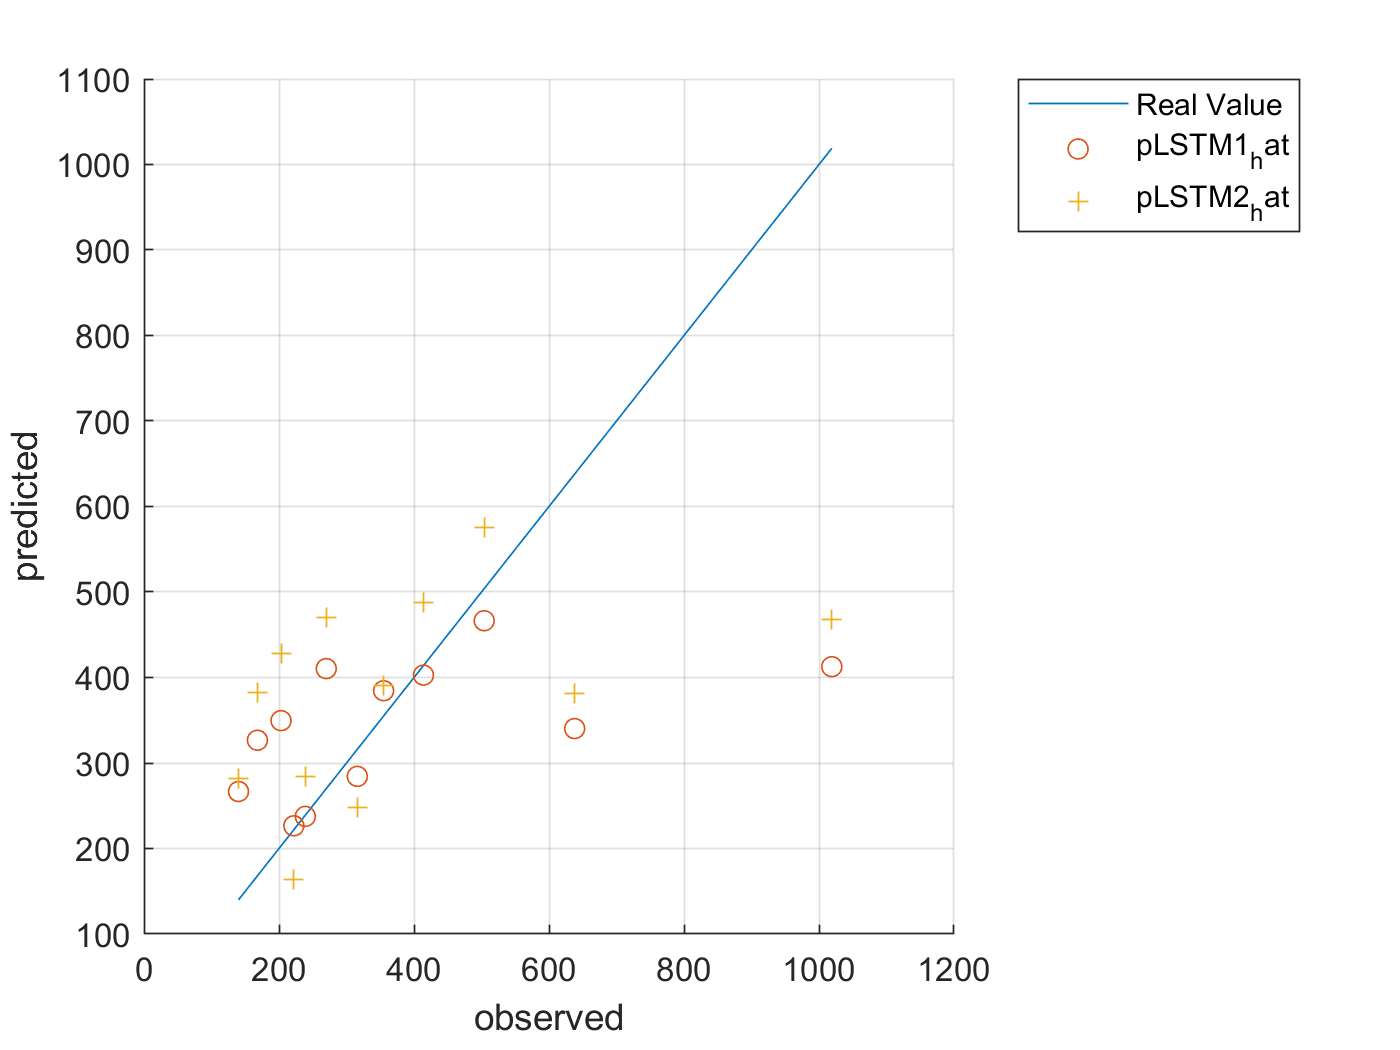

pLSTM2 = cell2mat(predict(netLSTM2, num2cell(xnorm_IcFirst_RUL(idxTestSort, :)', 1)));
ytest = ynorm_IcFirst_RUL(idxTestSort, :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM1_hat = pLSTM1 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM2_hat = pLSTM2 * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
rmse_pLSTM1_hat = sqrt(mean(( ytest' - pLSTM1_hat' ).^2))
rmse_pLSTM2_hat = sqrt(mean(( ytest' - pLSTM2_hat' ).^2))
y_test_diff_percentage_LSTM_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pLSTM1_hat')./Y_test_IcFirst_RUL'.*100)/length(abs(Y_test_IcFirst_RUL'-pLSTM1_hat')./Y_test_IcFirst_RUL')
y_test_diff_percentage_LSTM2_hat_avg = sum(abs(Y_test_IcFirst_RUL'-pLSTM2_hat')./Y_test_IcFirst_RUL.*100')/length(abs(Y_test_IcFirst_RUL'-pLSTM2_hat')./Y_test_IcFirst_RUL')

figure, hold on, grid on,
plot(ytest,ytest)
plot(ytest,pLSTM1_hat,'o')

plot(ytest,pLSTM2_hat,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_hat', ...
        'pLSTM2_hat','Location','northeastoutside')


rmse_pLSTM1_self_hat = single
198.8112

rmse_pLSTM2_self_hat = single
207.3420

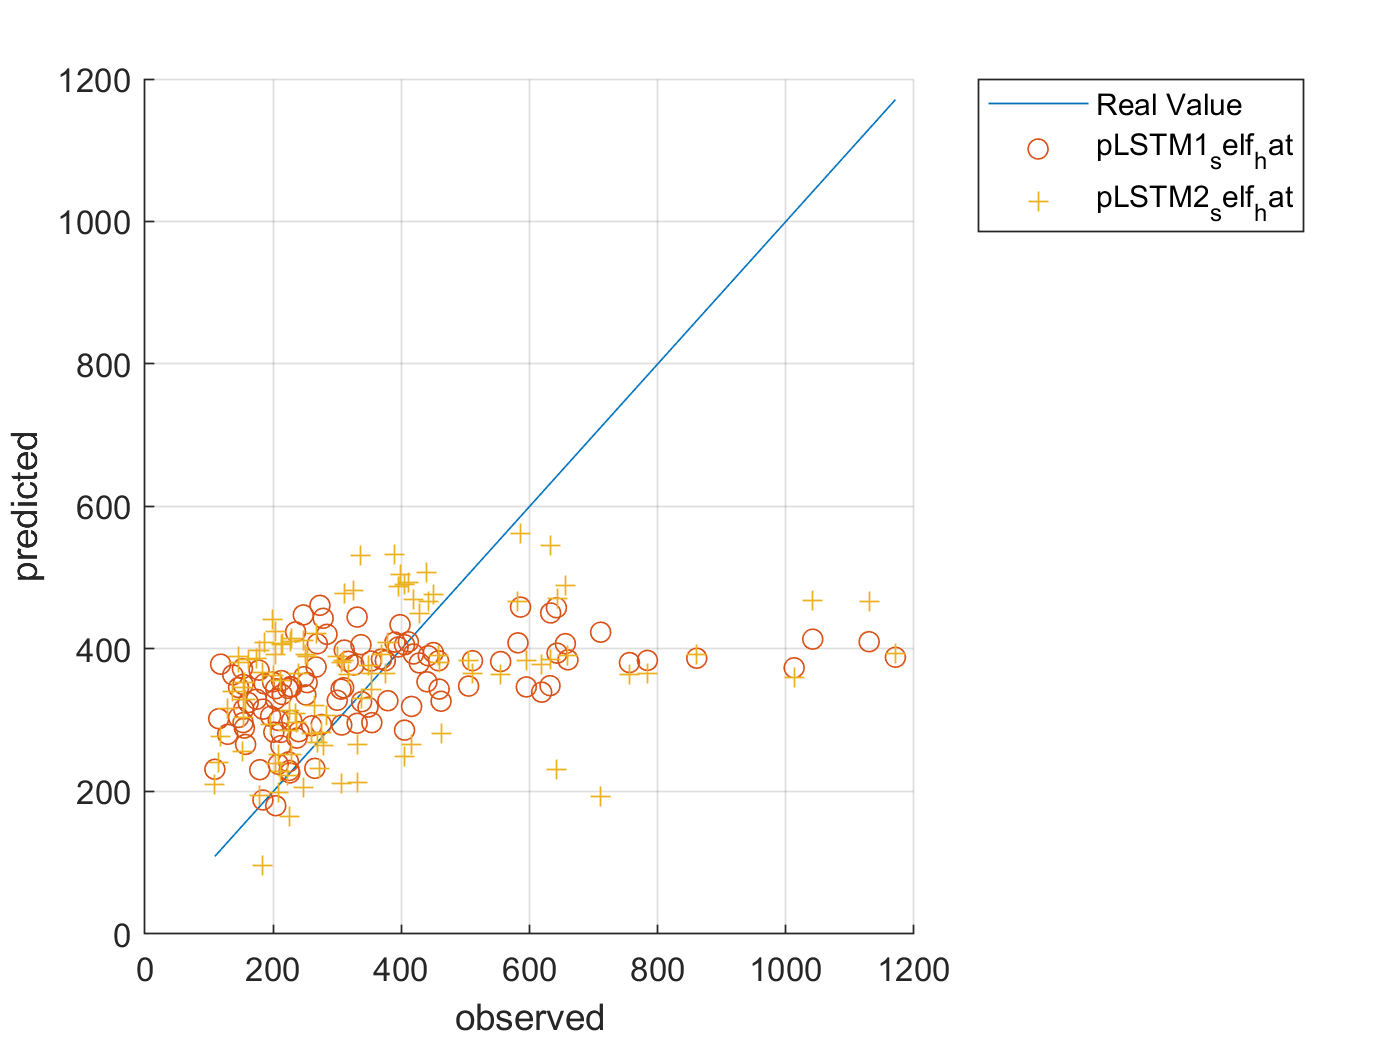


pLSTM1_self = cell2mat(predict(netLSTM1, num2cell(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)', 1)));
pLSTM2_self = cell2mat(predict(netLSTM2, num2cell(xnorm_IcFirst_RUL([idxTrainSort idxValidSort], :)', 1)));
ytrain_self = ynorm_IcFirst_RUL([idxTrainSort idxValidSort], :)*yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM1_self = pLSTM1_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
pLSTM2_self = pLSTM2_self * yrate_IcFirst_RUL + ymin_IcFirst_RUL;
rmse_pLSTM1_self_hat = sqrt(mean(( ytrain_self' - pLSTM1_self' ).^2))
rmse_pLSTM2_self_hat = sqrt(mean(( ytrain_self' - pLSTM2_self' ).^2))

figure, hold on, grid on,
plot(ytrain_self,ytrain_self)
plot(ytrain_self,pLSTM1_self,'o')

plot(ytrain_self,pLSTM2_self,'+')
hold off

xlabel 'observed'
ylabel 'predicted'
legend(	'Real Value', ... 
		'pLSTM1_self_hat', ...
        'pLSTM2_self_hat','Location','northeastoutside')
